# Feedback Controls Course Project

Spring 2026

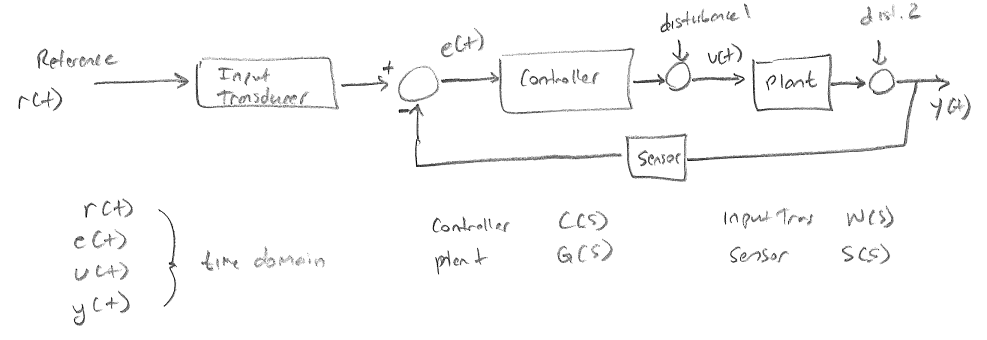

## Welcome!  

The course project is an exciting time to take the material learned and applied in this course and use it on a project of your choice!  Before getting into the excitement of the project, let's cover the paperwork side of things.  From your careful analysis of ELC, you've noticed that overall the final course project is worth **38%** of the course grade.  So, to keep you on track to do well, there are 3 main checkpoints and 1 demonstration day.  See the course schedule and ELC for the due dates for each.  

The burning question... If you are in the 4220 section, you can work in pairs, *or* choose to work alone.  If you are in the 6220 section you must work alone.  The next paperwork issue, is that there are tiers to this report.  Choose to work to what you'd like!  Let's abbreviate "feedback control system" with FBC.  

### Minimum to be considered for a 65%

- Your FBC meets all the system constraints and document expectations (coming later...).

- Your FBC has a working Livescript file that calls a working Simulink simulation.

- In your Simulink simulation you have a Simscape simulation matching your plant.  

- The Livescript uses data from the Simulink Simulation to make plots and figures.  

### Minimum to be considered for a 75%

- You have all of the above AND you have linearized the system about an operating point.  In your code you can change where this operating point is.  This also implies you have derived the mathematics associated with your plant.  

### Minimum to be considered for an 85%

- You have all of the above AND you have implemented a *working* FBC on pre-existing hardware.  

### Minimum to be considered for a 100%

- You have all of the 75% tier AND you have implemented a *working* *FBC on **raw** hardware *you have made during the duration of this class*.  This excludes Capstone projects and other projects where the majority of the work has been completed or funded. Those would fall in the 85% tier.  

**WARNINGS**

- There's a lot of great resources out there!  You must cite the source.  This includes any 3D printing files or anything else used.  

- Copy and pasting [https://github.com/MathWorks-Teaching-Resources/Virtual-Controls-Laboratory](https://github.com/MathWorks-Teaching-Resources/Virtual-Controls-Laboratory) from here or other Mathworks will move you to the 65% tier.  The only permissible copying is Simscape files.  

## Checkpoint 1: Magnetic Levitator

#### Background

Insert a motivational photograph of your desired FBC.  

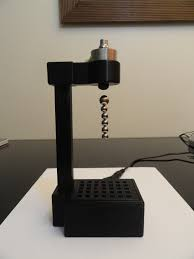

Figure 1. Magnetic Levitator

## **Write a paragraph description describing your desired FBC. **

   The magnetic levitator is a closed-loop feedback control system designed to suspend a permanent magnet at a fixed position beneath an electromagnet. The electromagnet is constructed by wrapping copper wire around a cylindrical ferromagnetic core, forming an inductive coil. When current flows through the coil, a magnetic field is generated, producing an attractive force on the magnet. The microcontroller regulates the strength of this magnetic field by controlling the average current through the coil using pulse width modulation (PWM). A Hall-effect sensor positioned at the bottom of the electromagnetic coils measures the local magnetic flux density. Because the magnetic field produced by the permanent magnet varies with distance, the Hall sensor output changes as the magnet moves relative to the sensor. This measurement is fed back into the controller, which adjusts the PWM duty cycle to increase or decrease the coil current, thereby regulating the magnetic force acting on the magnet and maintaining the desired levitation height. 

## **Write a paragraph on the history of your FBC.  Tell the story from when it was first invented/studied to modern day.  Insert photos or links to keep the reader interested.  It's a paragraph, not a chapter. **

    The concept of magnetic levitation (maglev) was first conceived in the early 20th century by Robert Goddard and Emile Bachelet, who first proposed the concept of frictionless travel using electromagnetic repulsion. By 1912, Bachelet had successfully demonstrated a model train that utilized AC solenoids for propulsion, though the technology remained largely theoretical for decades. In the mid 20th century, efforts finally began to develop a high-speed rail system using this technology. In 1966, James Powell and Gordon Danby of Brookhaven National Laboratory proposed the use of superconducting magnets for levitation. Commercial implementation finally took root in the late 20th and early 21st centuries [4]. The first commercial low-speed maglev opened in Birmingham, England, in 1984, followed by Berlin's automated M-Bahn in 1989 [4]. While these early European lines were eventually decommissioned, China successfully launched the Shanghai Maglev in 2004, which remains the world’s only high-speed commercial line, reaching speeds of up to 268 mph. Modern development is now led by Japan’s SCMAGLEV system, which set a world speed record of 374 mph in 2015 [4]. Even though development has slowed on practically applying maglev for transportation needs, the technology is proven to be a viable alternative to conventional rail and air travel.

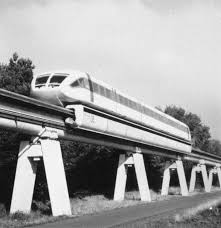

Figure 2.

## **Write a paragraph on a literature study of existing projects similar to yours. Include links and photos as appropriate.  **

    When searching on the internet, we found that some were able to build a variation of our project, with some variations on the application or planned implementation. The first study we found was a magnetic train rail system, that used normal magnets to levitate a wooden block that could be moved on a rail system. This project was not directly applicable to our project, but the concept of using magnets to levitate an object at a constant distance is a principle that we will use.

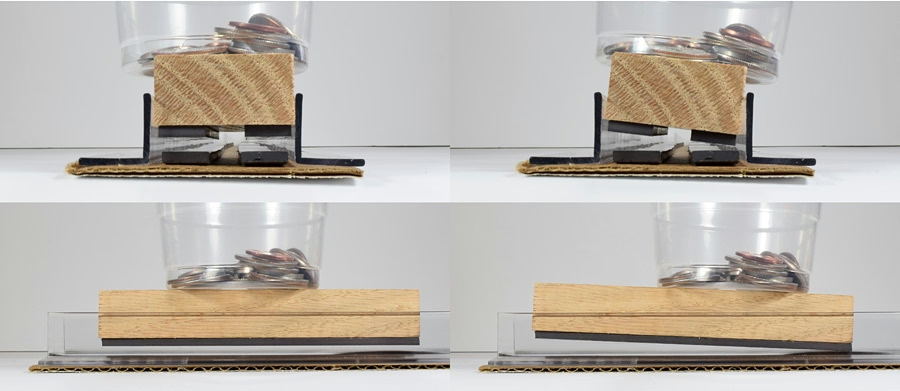

Figure 3.

    Another project that we found was a levitating light project, that is much more applicable to what we are doing. However, instead of using a magnet as a load, the creator fabricated their own magnet using a coil of wire, rather than a permanent magnet. As a result, there is additional circuitry that is needed to wirelessly transfer power from the electromagnet to the light magnet, which we will not be using (we are using a permanent magnet).

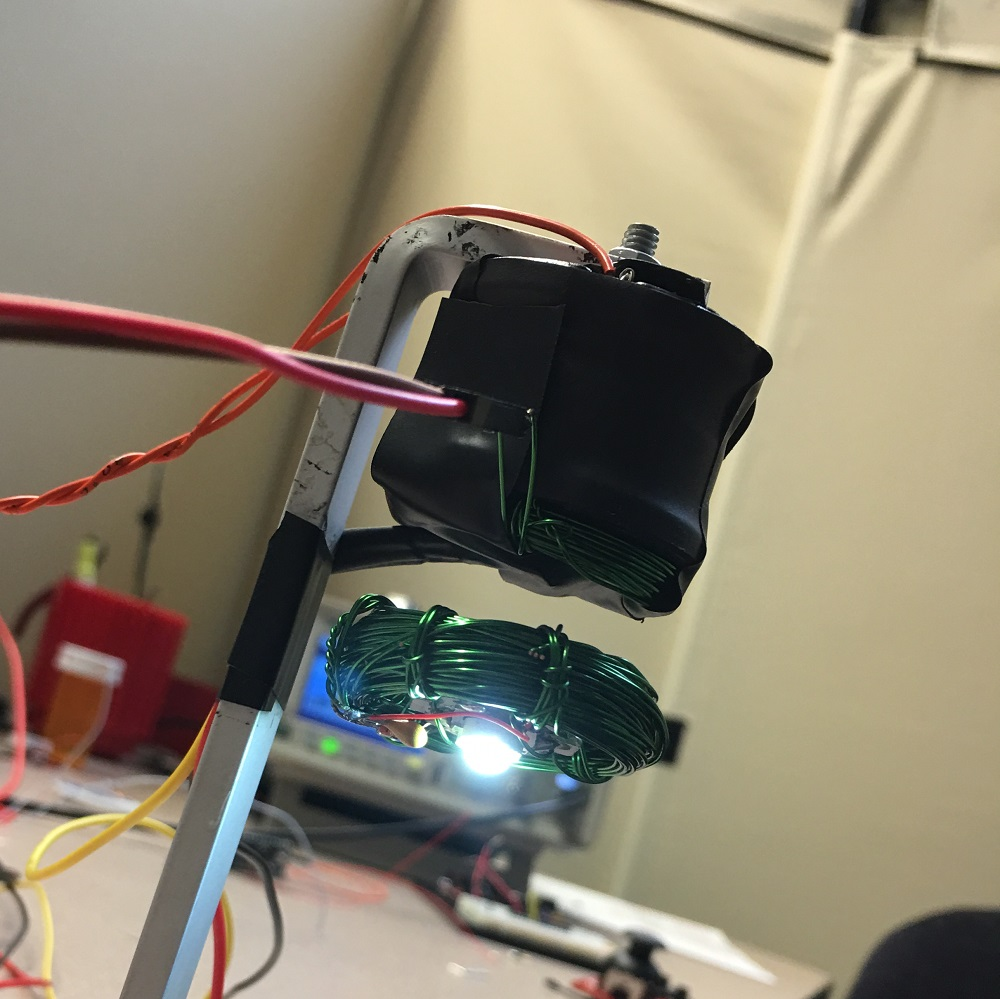

Figure 4. Floating Magnetic Transformer

Train Project: [*https://www.sciencebuddies.org/science-fair-projects/project-ideas/Phys_p093/physics/maglev-train-weight*](https://www.sciencebuddies.org/science-fair-projects/project-ideas/Phys_p093/physics/maglev-train-weight)

*Levitating Light:** https://github.com/awende/Levitating_Light/tree/master*

## ***Give a mathematical description of your system.  ***$\dot{x} =f\left(x\right)$

- **Be sure to use actual equation formatting.  **

- **Be sure to define all parameters.  Be sure to define all units.  **

- **Include any plots or diagrams necessary to support the underlying dynamics.  **

- **Include references of works you are using.  **

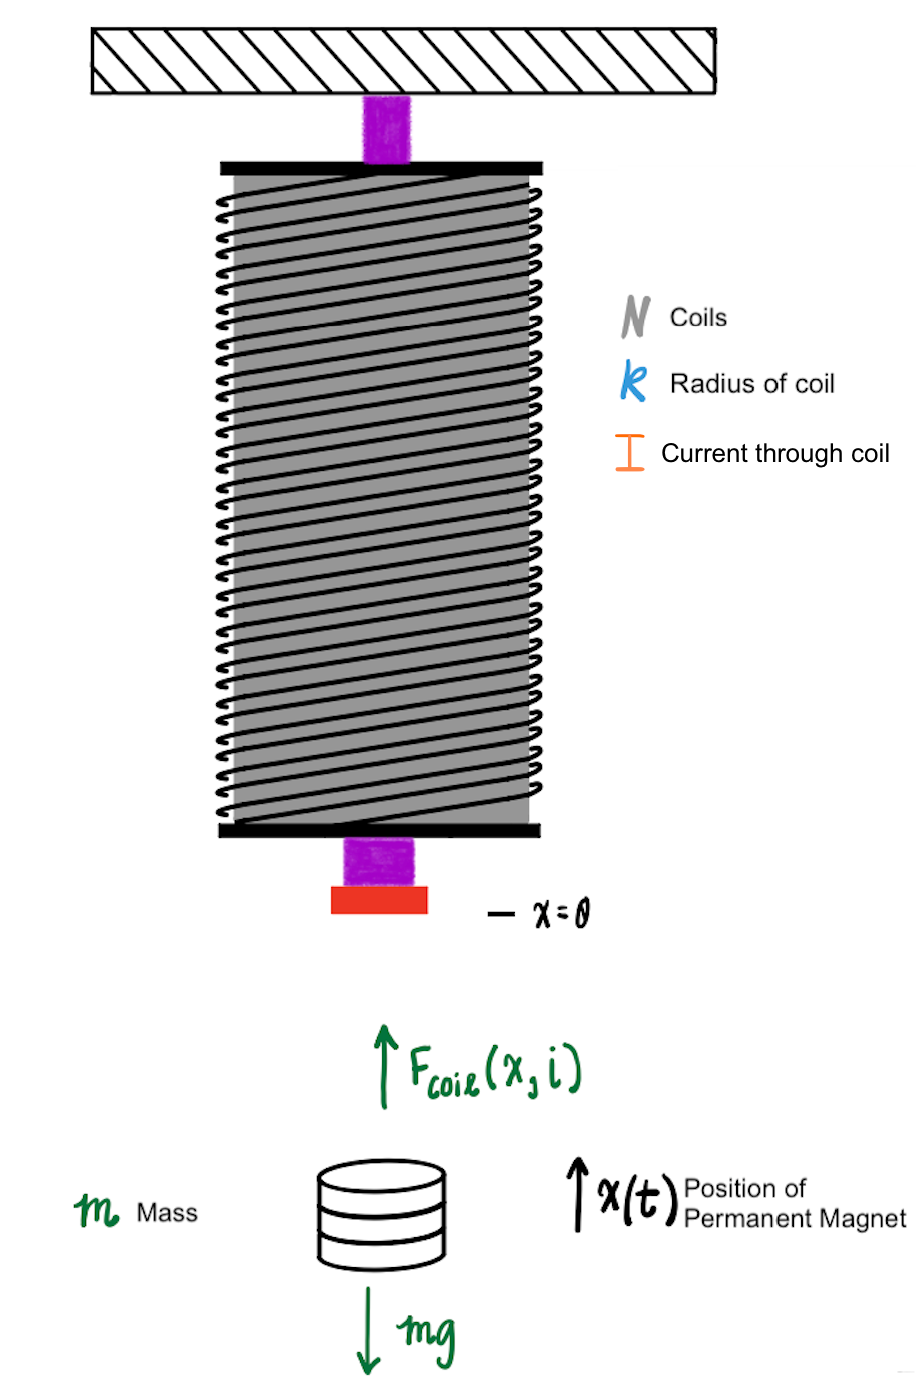

Figure 5. Levitator Schematic and FBD

    The above image gives a baseline model of the magnetic levitation system. The inductor will act as an electromagnet that produces a magnetic field that attracts the permanent magnet and causes it to levitate. Variables are defined according to the coil: $N$number of coils in the inductor, $R$ radius of the coil loop (m), and $I$ current through the coils (A), which is the input of the feedback control system. The permanent magnet has a mass $m$ (kg) and an output variable $x$, which is the position relative to the base of the inductor coils (m). Let us begin with the fundamental equation of physics: $F=\textrm{ma}\ldotp$ For simplicity, for the duration of the final report, *coils* will be used to describe the electromagnet inductor and *magnet* will be used to describe the levitating permanent magnet. $m\ddot{x} =F_{\textrm{coils}} \left(x,i\right)-\textrm{mg}$ where $F_{\textrm{coils}} \left(x,i\right)$ is the magnetic force of the coils attracting the magnet, not yet defined mathematically. There is also a force of gravity that opposes the upwards movement of the magnet. Finally, at this stage in modeling, any dampening effects or disturbances will be ignored. 

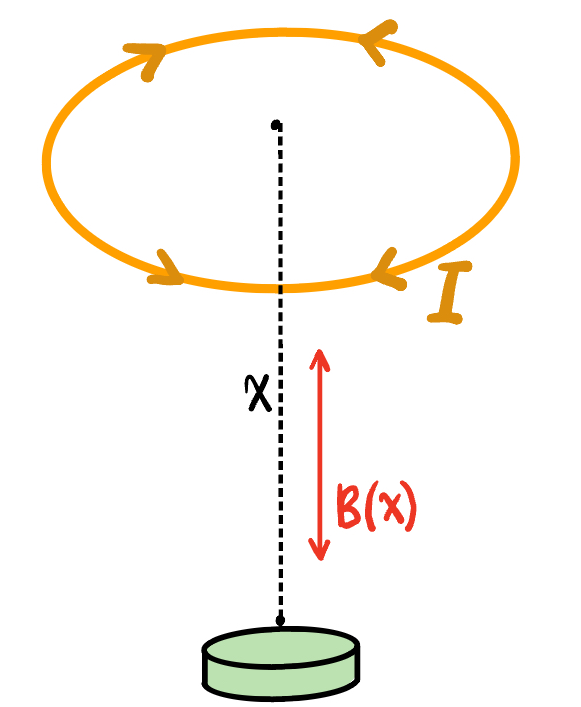

Figure 6. Biot-Savart Law of Single Loop

    The electromagnetic phenomena must be defined to properly define this second order non linear system. According to the Biot-Savart Law, for a circular loop of radius $R$ carrying current $I$, the magnetic field strength at a distance $x$ from the center along the axis is $B\left(x,I\right)=\frac{\mu_0 {\textrm{IR}}^2 }{2{\left(x^2 +R^2 \right)}^{\frac{3}{2}} }$, where $B\left(x\right)\;$is the magnetic flux density (T) as a function of position from the center, $\mu_0 \;$is the permeability of free space (H/m), and $N,I,x,R$ have been previously defined. In the orientation of our magnetic levitator and ignoring any inconsistencies of physical orientation, we can define the magnetic field as pointing directly axialy and perpendicular to the coil loop, according to the Right Hand Rule. This magnetic field orientation is displayed in the figure above. Because magnetic fields obey the principle of superposition, the magnetic field produced by an electromagnet consisting of $N$ identical circular coils carrying current $I$ can be approximated as the sum of the fields produced by each loop individually, resulting in the axial magnetic field expression: [1]

$B\left(x,I\right)=\frac{N\mu_0 {\textrm{IR}}^2 }{2{\left(x^2 +R^2 \right)}^{\frac{3}{2}} }$. 

    At this point, the magnetic force on the permanent magnet, $F_{\textrm{coils}} \left(x,i\right)$ is still not fully defined. The force acting on a magnetic dipole in a non-uniform magnetic field can be expressed using the dipole force relation: $\vec{F} =\nabla \left(\vec{m} \cdot \vec{B} \right)$where $\vec{F}$is the magnetic force vector (N), $\vec{m}$ is the magnetic dipole moment vector of the permanent magnet (${\textrm{Am}}^2$), and $\vec{B}$ is the magnetic flux density vector at the magnetic location (T). [2] The gradient operator tells that the force on a magnetic object in a non-uniform field is proportional to the spatial gradient (the rate of change) of that field. Furthermore this gradient is equal to the vector of partial derivatives of a scalar field. Thus, $\nabla B=\left\lbrack \begin{array}{c}
\frac{\partial f}{\partial x}\\
\frac{\partial f}{\partial y}\\
\frac{\partial f}{\partial y}
\end{array}\right\rbrack$. [3] In the magnetic levitation configuration shown in Figure 1, the permanent magnet moves only along the central axis of the coil. Due to the cylindrical symmetry of the circular coil, the magnetic field has no horizontal components and only varies along the axial direction. Consequently, the gradient reduces to a single derivative along the axis of motion. The dipole force on the magnet expression is therefore simplified to $F_{\textrm{coils}} \left(x,i\right)=m_d \frac{\textrm{dB}}{\textrm{dx}}$ where $m_d$ is the magnitude of the magnetic dipole moment of the permanent magnet (${\textrm{Am}}^2$) and $\frac{\textrm{dB}}{\textrm{dx}}$ is the spatial gradient of the magnetic field along the coil axis (T/m). 

    The derivative of $B\left(x\right)$ must be found as such:


$$\frac{\textrm{dB}}{\textrm{dx}}=\frac{d}{\textrm{dx}}\left\lbrack \frac{N\mu_0 {\textrm{IR}}^2 }{2}\cdot {\left(x^2 -R^2 \right)}^{\frac{-3}{2}} \right\rbrack =-\frac{3N\mu_0 {\textrm{IR}}^2 x}{2{\left(x^2 +R^2 \right)}^{\frac{5}{2}} }$$


    Therefore, the magnetic force produced by the coil acting on the magnet can be written as

$F_{\textrm{coils}} \left(x,I\right)=\frac{3\mu_0 N{\textrm{IR}}^2 m_d x}{2{\left(x^2 +R^2 \right)}^{\frac{5}{2}} }\;$. 

where the sign will depend on the defined coordinate convention. Finally, substituting this force into Newtown's second law as previosly explained provides the basic nonlinear second-order model of the levitation system: 


$$m\ddot{x} =\frac{3\mu_0 N{\textrm{IR}}^2 m_d x}{2{\left(x^2 +R^2 \right)}^{\frac{5}{2}} }-\textrm{mg}$$
 

## Give discussion on a nominal model vs calibration model.  

    In the context of feedback control systems, a nominal model and a calibration model boil down to a theoretical expectation of how a system will behave, and the physical reality of how the model behaves. A nominal model is the baseline mathematical representation of a system built purely from first principles (physics, kinematics, or circuit theory) and ideal assumptions. It often ignores messy, nonlinear real-world factors to keep the math manageable by assuming factors such as zero friction, perfectly rigid materials, or perfectly uniform magnetic fields. The model above initially ignores any air damping, magnetic field interactions with the coil geometry, Hall sensor dynamics, eddy currents, and more. 

    A calibration model is obtained after experimental data from the physical system is used to adjust the parameters of the nominal model so that the model more accurately reflects the actual system behavior. This is obtained after taking the nominal model and mathematically tuning its parameters so that its outputs match the actual data collected from the physical hardware. Calibration helps capture un-modeled dynamics and hardware imperfections, so if the physical system responds slower than the nominal math predicts, the calibration process adjusts factors like damping or inertia to bridge that gap. By fitting the model parameters to measured data, the calibrated model produces predictions that better match the real system response and can therefore be used more reliably for controller design and performance analysis.

## Using your mathematical description, describe the "ails" of your open-loop system. 

- Include any plots, diagrams, etc to support your discussion. 

- The best feedback controller is no feedback controller as you have a system that behaves exactly how you want.  Explain the dynamics of your system and what (if any) structural changes you can make to the plant to get better open-loop performance. Without applying feedback control.  

    Using the nonlinear dynamic model derived earlier, $m\ddot{x} =\frac{3\mu_0 N{\textrm{IR}}^2 m_d x}{2{\left(x^2 +R^2 \right)}^{\frac{5}{2}} }-\textrm{mg}$, the motion of the permanent magnet depends on the difference between the magnetic force generated by the electromagnet and gravity. The magnetic force is a nonlinear function of coil current $I$ and magnet position $x$. 

    Considering the system as open loop, then the current $I$ would be fixed. Equilibrium or a steady state condition would be when there is no acceleration and the net force on the magnet is zero, $\frac{3\mu_0 N{\textrm{IR}}^2 m_d x_e }{2{\left(x^2 +R^2 \right)}^{\frac{5}{2}} }=\textrm{mg}$ where $x_e$ is the equilibrium levitation height. 

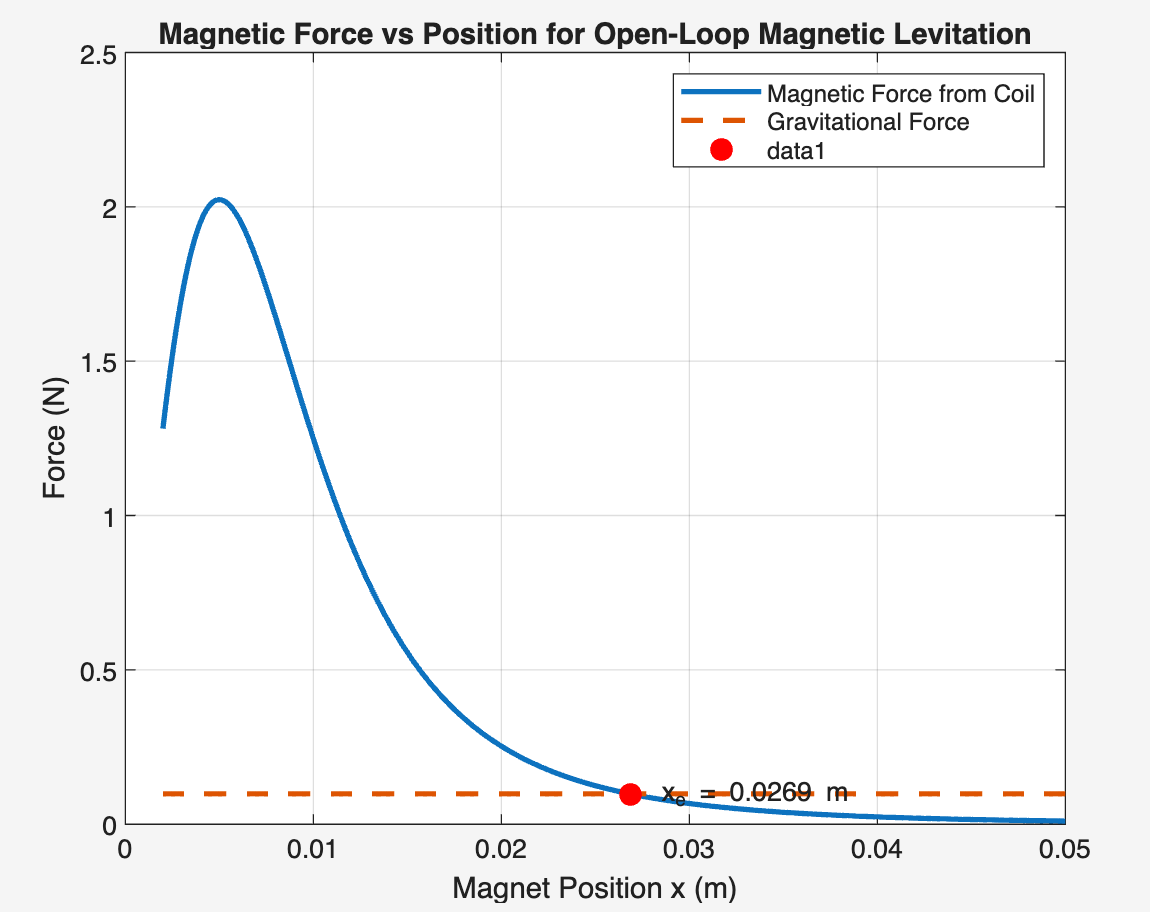

Figure 7. Magnetic Force Vs. Position (N=500, I=1.5, R=.01,md=0.5,m=.01,g=9.81)

    Figure 7 shows the magnetic force produced by the coil as a function of magnet position for a fixed open-loop current, with the constant gravitational force. The intersection of these two curves represents the theoretical equilibrium position $x_e$, where the upward magnetic force exactly balances the downward gravitational force. However, this equilibrium is unstable. For positions slightly greater than $x_e$, the magnetic force becomes smaller than gravity, causing the magnet to fall downward. For positions less than $x_e$ the magnetic force exceeds gravity, causing the magnet to accelerate upward. Therefore, although the open-loop system has a theoretical equilibrium point, it cannot maintain levitation without feedback control.The unstable behavior is as follows: 

- If the magnet moves slightly upward, the magnetic force increases, causes the magnet to accelerate upwards and collide with the coils. The converse exists in the opposite direction when the magnet moves slightly downwards and will fall. 

   Furthermore, the force term $F_{\textrm{coils}} \left(x,i\right)=\frac{3\mu_0 N{\textrm{IR}}^2 m_d x}{2{\left(x^2 +R^2 \right)}^{\frac{5}{2}} }\;$is nonlinear with respect to position as small changes in distance cause large changes in force, making the open-loop system unstable. 

### Improvements

    There exist some physical modifications to the system in order to force the plant into better open-loop performance. 

- Increasing the coil radius $R$ or number of turns $N$: This will increase the achievable magnetic force and may allow the magnet to levitate at further distances with less effect to the change in position. This will reduce sensitivity to position disturbances. 

- Improve mechanical alignment: Ensure that the magnet remains constrained to moving only along the central axis to ensure the assumptions of ignoring $y,z$ magnetic field orientations do not affect the model. 

- Optimize Coil Geometry: The geometry of the electromagnet affects the magnetic field distribution. Designing the coil with a uniform radius and proper material will help produce a smoother and more predictable magnetic field gradient, matching the assumptions of the math model. 

- Limiting Eddy Currents: Eddy currents are circulating currents in nearby conductive materials that oppose the original magnetic field. These can be introduced in nearby conductive components such as the electromagnet core, the mounting structure, or other metallic supports. These effects can be reduced by laminating the magnet cores, or using insulalting layers between conductive materials. 

#### Simulation

% Use MATLAB to define parameters and equations.  NOTE at this point many parameters may not be fully known if you are going for higher grades.  This is ok, for now choose an initial guess.  

set(0, 'DefaultAxesXLimMode', 'auto');
set(0, 'DefaultAxesYLimMode', 'auto');

m = 0.01;         % Mass (kg) (estimated)
g = 9.81;         % Gravity (m/s^2)
R = 15;            % Coil Resistance (Ohms)
L = 0.04;         % Coil Inductance (H)
N = 1000;          % Number of turns
R_coil = 0.01;    % Coil radius (m)
m_mag = 0.5;      % Magnetic moment (A*m^2)
mu0 = 4*pi*1e-7;  % Permeability of free space

% Lumped force constant
K_force = (3 * mu0 * N * m_mag * R_coil^2) / 2;

% Target hover height
x0 = 0.5 * 0.0254;   % 1/2 inch = 0.0127 m

Then create a Simulink simulation of your model that is called from those parameters.  

% insert a call to Simulink...
model_name = 'MagneticLevitator';
out = sim(model_name)

out =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
         simout_current: [1x1 timeseries] 
           simout_force: [1x1 timeseries] 
             simout_vel: [1x1 timeseries] 
                   tout: [256x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Use a SIMOUT block to take your results back here and create visually appealing plots.  

- Show key results from the open-loop simulation

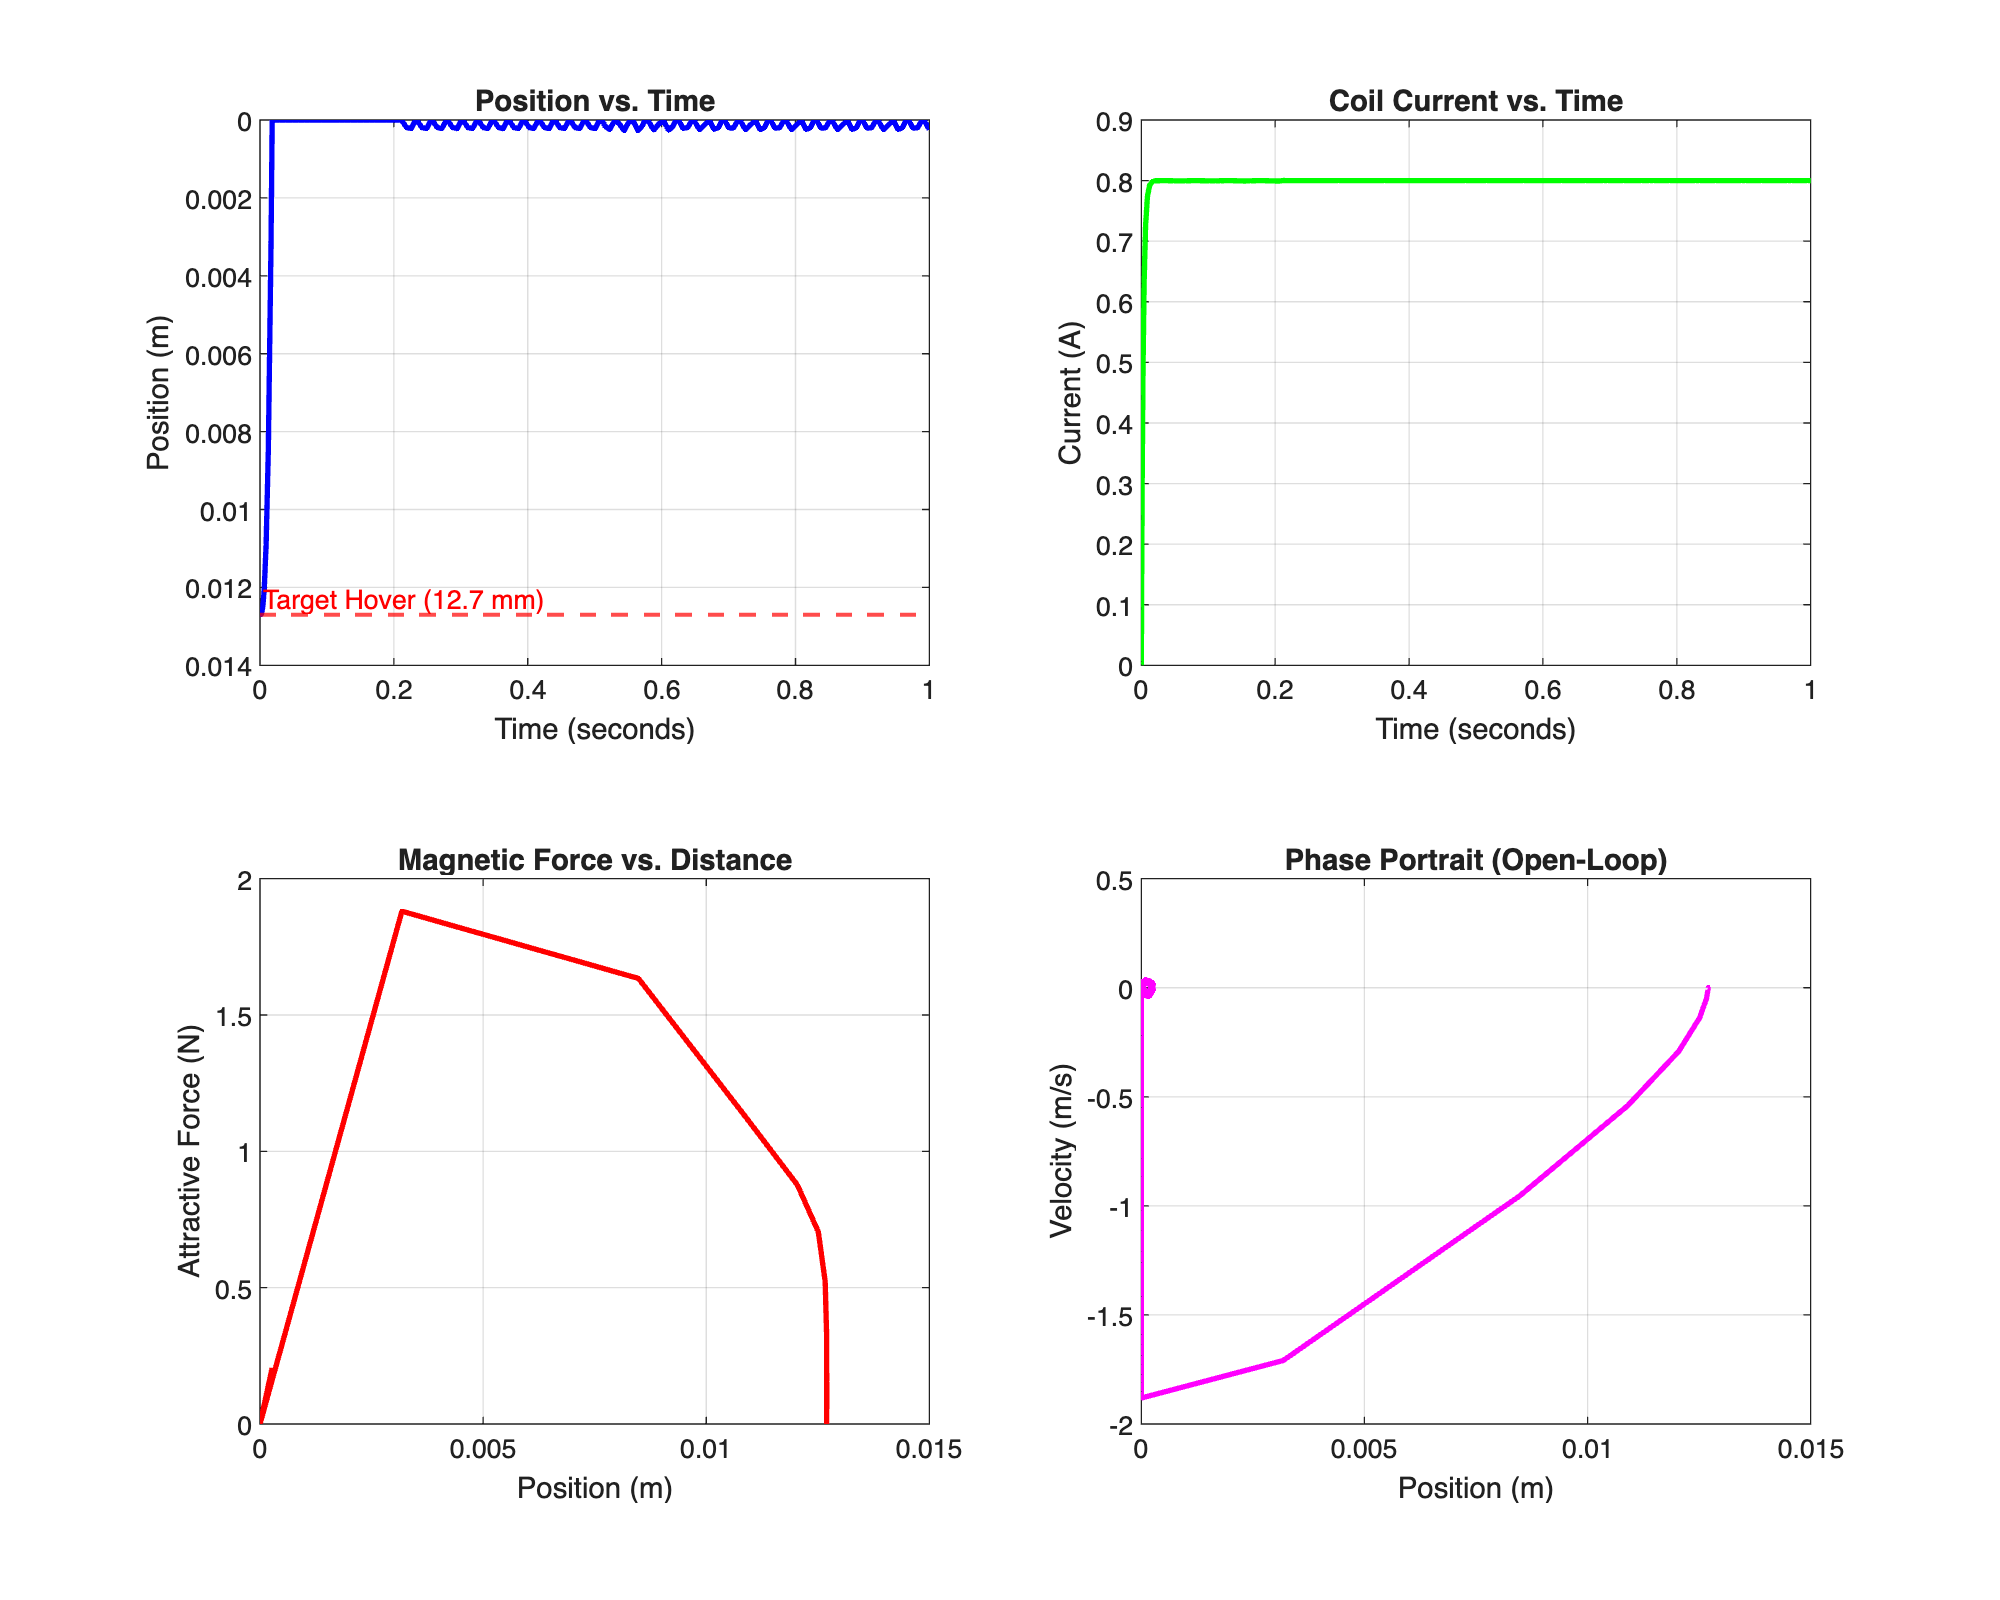

% Create plots
time = out.simout.Time;
pos = out.simout.Data;
force = out.simout_force.Data;
current = out.simout_current.Data;
vel = out.simout_vel.Data;

figure('Position', [100, 100, 1000, 800]);

subplot(2,2,1);
plot(time, pos, 'b-', 'LineWidth', 2); % Position in m
hold on;
yline(0.0127, 'r--', 'Target Hover (12.7 mm)', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left');
hold off;
grid on;
title('Position vs. Time');
xlabel('Time (seconds)');
ylabel('Position (m)');
set(gca, 'YDir', 'reverse');

subplot(2,2,2);
plot(time, current, 'g-', 'LineWidth', 2);
grid on;
title('Coil Current vs. Time');
xlabel('Time (seconds)');
ylabel('Current (A)');

subplot(2,2,3);
plot(pos, force, 'r-', 'LineWidth', 2); 
grid on;
title('Magnetic Force vs. Distance');
xlabel('Position (m)');
ylabel('Attractive Force (N)');

subplot(2,2,4);
plot(pos, vel, 'm-', 'LineWidth', 2);
grid on;
title('Phase Portrait (Open-Loop)');
xlabel('Position (m)');
ylabel('Velocity (m/s)');

## Include a paragraph of analysis on the open-loop system.  

    As shown from the plots above, the system is inherently unstable in an open loop configuration when using a constant 5V input to the system. The **position versus time** plot shows that the magnet initially resting on the base rapidly accelerates toward the electromagnet once enough current is applied in the coil. The system is not able to keep the magnet suspended to the target height of 12.7mm, and the magnet is attracted to the coil and sticks to it, stuck at x = 0. This is due to the nonlinear dependance of force on distance. The **magnetic force versus distance plot** further illustrates the strong nonlinear relationship between force and position, showing that small changes in distance produce large changes in magnetic force.  Since the force of the coil is determined by the position of the magnet and the current through the coil, both must be controlled via feedback control in order to acheive the levitation effect. 

## Checkpoint 2: Sensors, Actuators, and Signals

Now we start building the Golden Model around your desired plant. 

### Sensors

## From a theoretical perspective, describe what measurements need to be made to your system.  

To acheieve effective control of the system, a controller must be designed around the open-loop model of the system that can detect difference between the observed and expected behavior of the plant. In the case of the magnetic levitator, the open loop system equation is governed by both the position of the magnet, and the current flowing through the coil. In order to create an effective control loop, the measurement of the position of the magnet, as well as the current flowing through the coil will be needed. 

## From a practical perspective, describe how you are going to make the measurements.  If you are going for a 75% you still need to include information about a hypothetical sensor.  

To measure the position of the magnet, a Hall-Effect sensor can be used. A linear Hall Effect Sensor such as the SS49E [1] will output an analog voltage that is proportional to the magnetic flux density of the area that is centered around half of the sensor's supply voltage when no field present. As the permanent magnet gets closer, the voltage shifts up or down depending on pole orientation. The analog output voltage of the sensor can be connected to an ADC pin on the microcontroller to get a reading of the magnet's position. To model the sensor, it can be described as a simple first order system that has a gain and a small time constant. The gain of the sensor will have to be found through physical tuning and experimentation, but the datasheet supplies the response time of the sensor, which is 3 microseconds. The system response of the hall effect sensor can be modeled as shown:


$$H_{\textrm{hall}} \left(s\right)=\frac{K_{\textrm{hall}} }{3{*10}^{-6} s+1}\;$$


 The Hall Effect sensor is planned to be powered by the 3.3V rail output from the microcontroller, giving us an effective resolution of around 2.6mV with a 12 bit ADC. According to the datasheet, the linear field range of the sensor is roughly 600 Gauss before saturation occurs, and has a sensitivity of 1.3mV/Gauss, which we determined is within the acceptable range of parameters for this project. 

To sense current in the system, a 0.1$\Omega$ shunt resistor will be tied to the output of the coil current, with a low-power opamp to amplify the signal to an acceptable measurement range, and a low pass fitler to block high frequency signal noise. The opamp will be in a non-inverting configuration, with a gain of 6.8k / 1k = 6.8. The gain of the system will be the shunt resistnace times the opamp gain, or 6.8 * 0.1 = 0.68V/A. The filter will have a cutoff frequency of around 1.6 kHz, with an RC of 1k and 100nf. The model for this system can also be described as a first order system, with a gain determined by the feedback resistors of the opamp, and the time constant being the pole of the low pass RC filter:


$$H_{\textrm{current}} \left(s\right)=\frac{K_{\textrm{current}} }{1{*10}^{-4} s+1}\;$$


The opamp that seems like a good choice for this application is the LM324N [2], which will be powered through the 5V rail. It has an operating temperature of -40 to 125 degrees Celcius, which is well within our physical temperature environment. It also has a voltage swing range from 0% to 98% of the supply voltage range, meaning that it will be able to provide an acceptable range of measurement for the current signal. For sampling rates, our plan is to integrate both of these sensors in a cascaded controller design (explained more below), with the current being the inner loop, and the position being the outer loop. For a cascaded controller, it is advised for the inner loop to sample at least 10x faster than the loop's bandwitdh. We are deciding to sample the hall effect sensor at 1 kHz, so the current sensor output will be sampled at 10 kHz. 

## Include links to datasheets, figures, photos, etc.  

[1] [Hall Effect Sensor](https://prod-edam.honeywell.com/content/dam/honeywell-edam/sps/siot/en-us/products/sensors/magnetic-sensors/linear-and-angle-sensor-ics/common/documents/sps-siot-ss39et-ss49e-ss59et-product-sheet-005850-3-en-ciid-50359.pdf)

[2] [Low Power Op Amp](https://www.ti.com/general/docs/suppproductinfo.tsp?distId=10&gotoUrl=http%253A%252F%252Fwww.ti.com%252Flit%252Fgpn%252Flm224)

*Include how you are modeling and powering the sensor.  Include your sample rate from the sensor.  Include physical limits.  *

% Code! 

% Hall Effect Sensor
K_hall = 150 % estimated, V/m

K_hall = 150

t_hall = 3e-6;
f_bw_hall = 1/(2*pi*t_hall);  % Sensor bandwidth (Hz)

hall_sensor_tf = tf(K_hall, [t_hall, 1]);
hall_sensor_tf


hall_sensor_tf =
 
      150
  -----------
  3e-06 s + 1
 
Continuous-time transfer function.


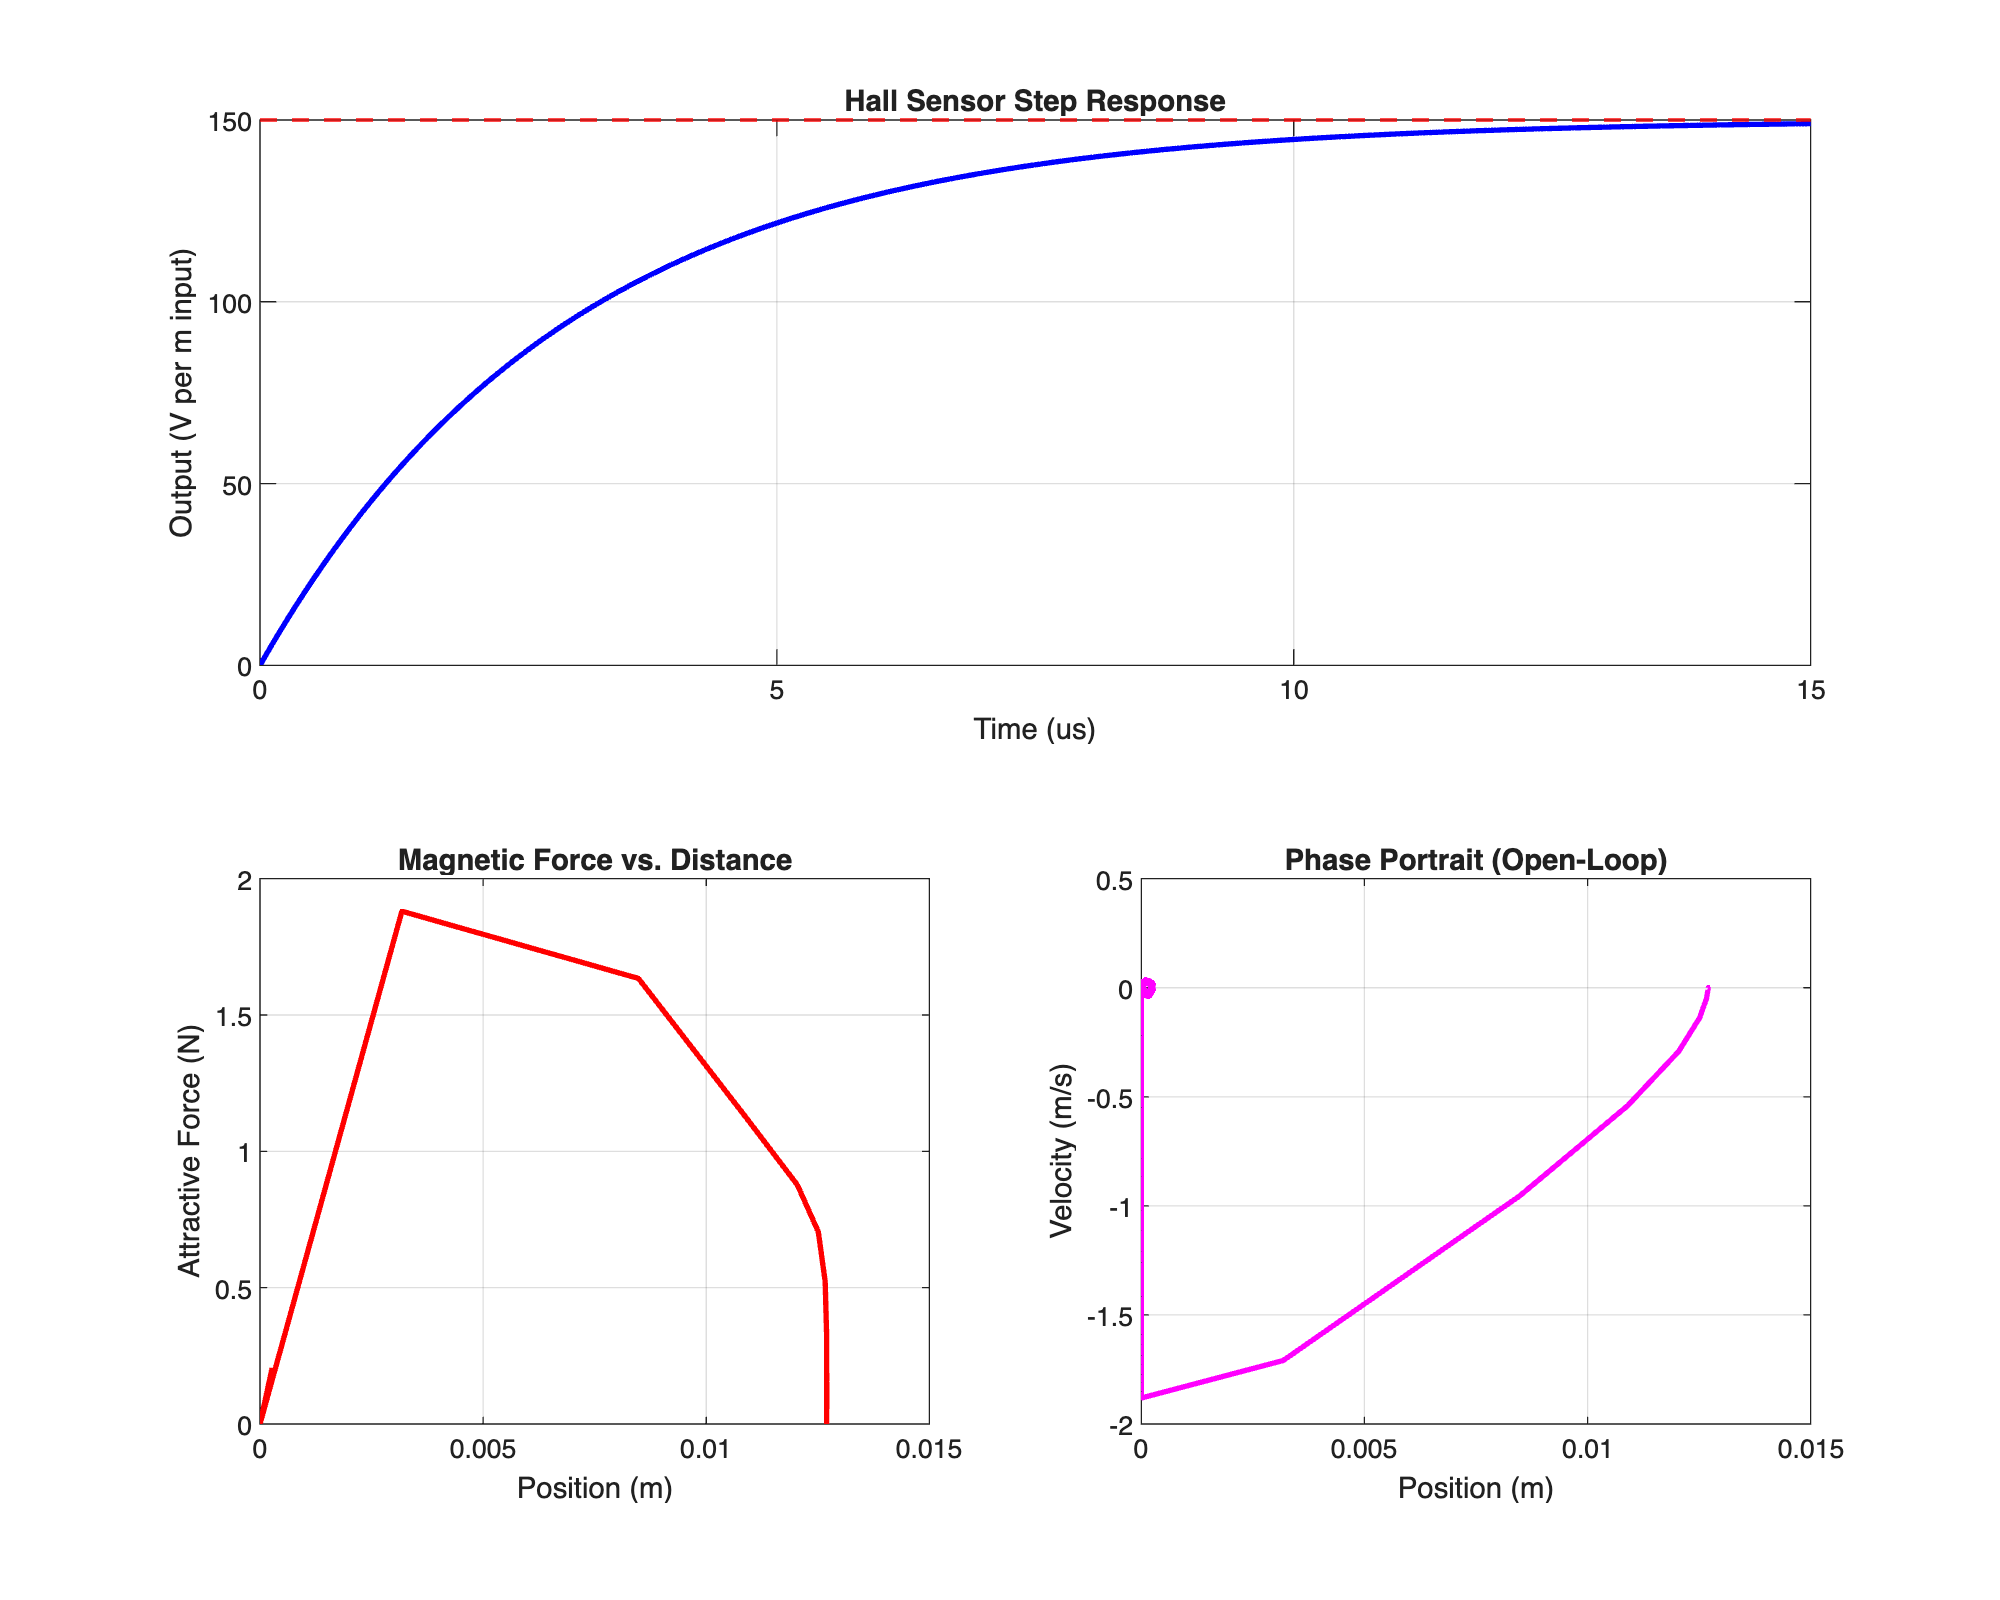

subplot(2, 1, 1);
t_h = linspace(0, 5*t_hall, 500);
[y_h, t_h_out] = step(hall_sensor_tf, t_h);
plot(t_h_out*1e6, y_h, 'b-', 'LineWidth', 2);
hold on;
yline(K_hall, 'r--', sprintf('K_{hall} = %.0f V/m', K_hall), 'LineWidth', 1.5);
xlabel('Time (us)');
ylabel('Output (V per m input)');
title('Hall Sensor Step Response');
grid on;


% Current Sensor
K_current = 0.78; % V/A
t_current = 1e-4;
current_sensor_tf = tf(K_current, [t_current, 1]);
current_sensor_tf


current_sensor_tf =
 
      0.78
  ------------
  0.0001 s + 1
 
Continuous-time transfer function.


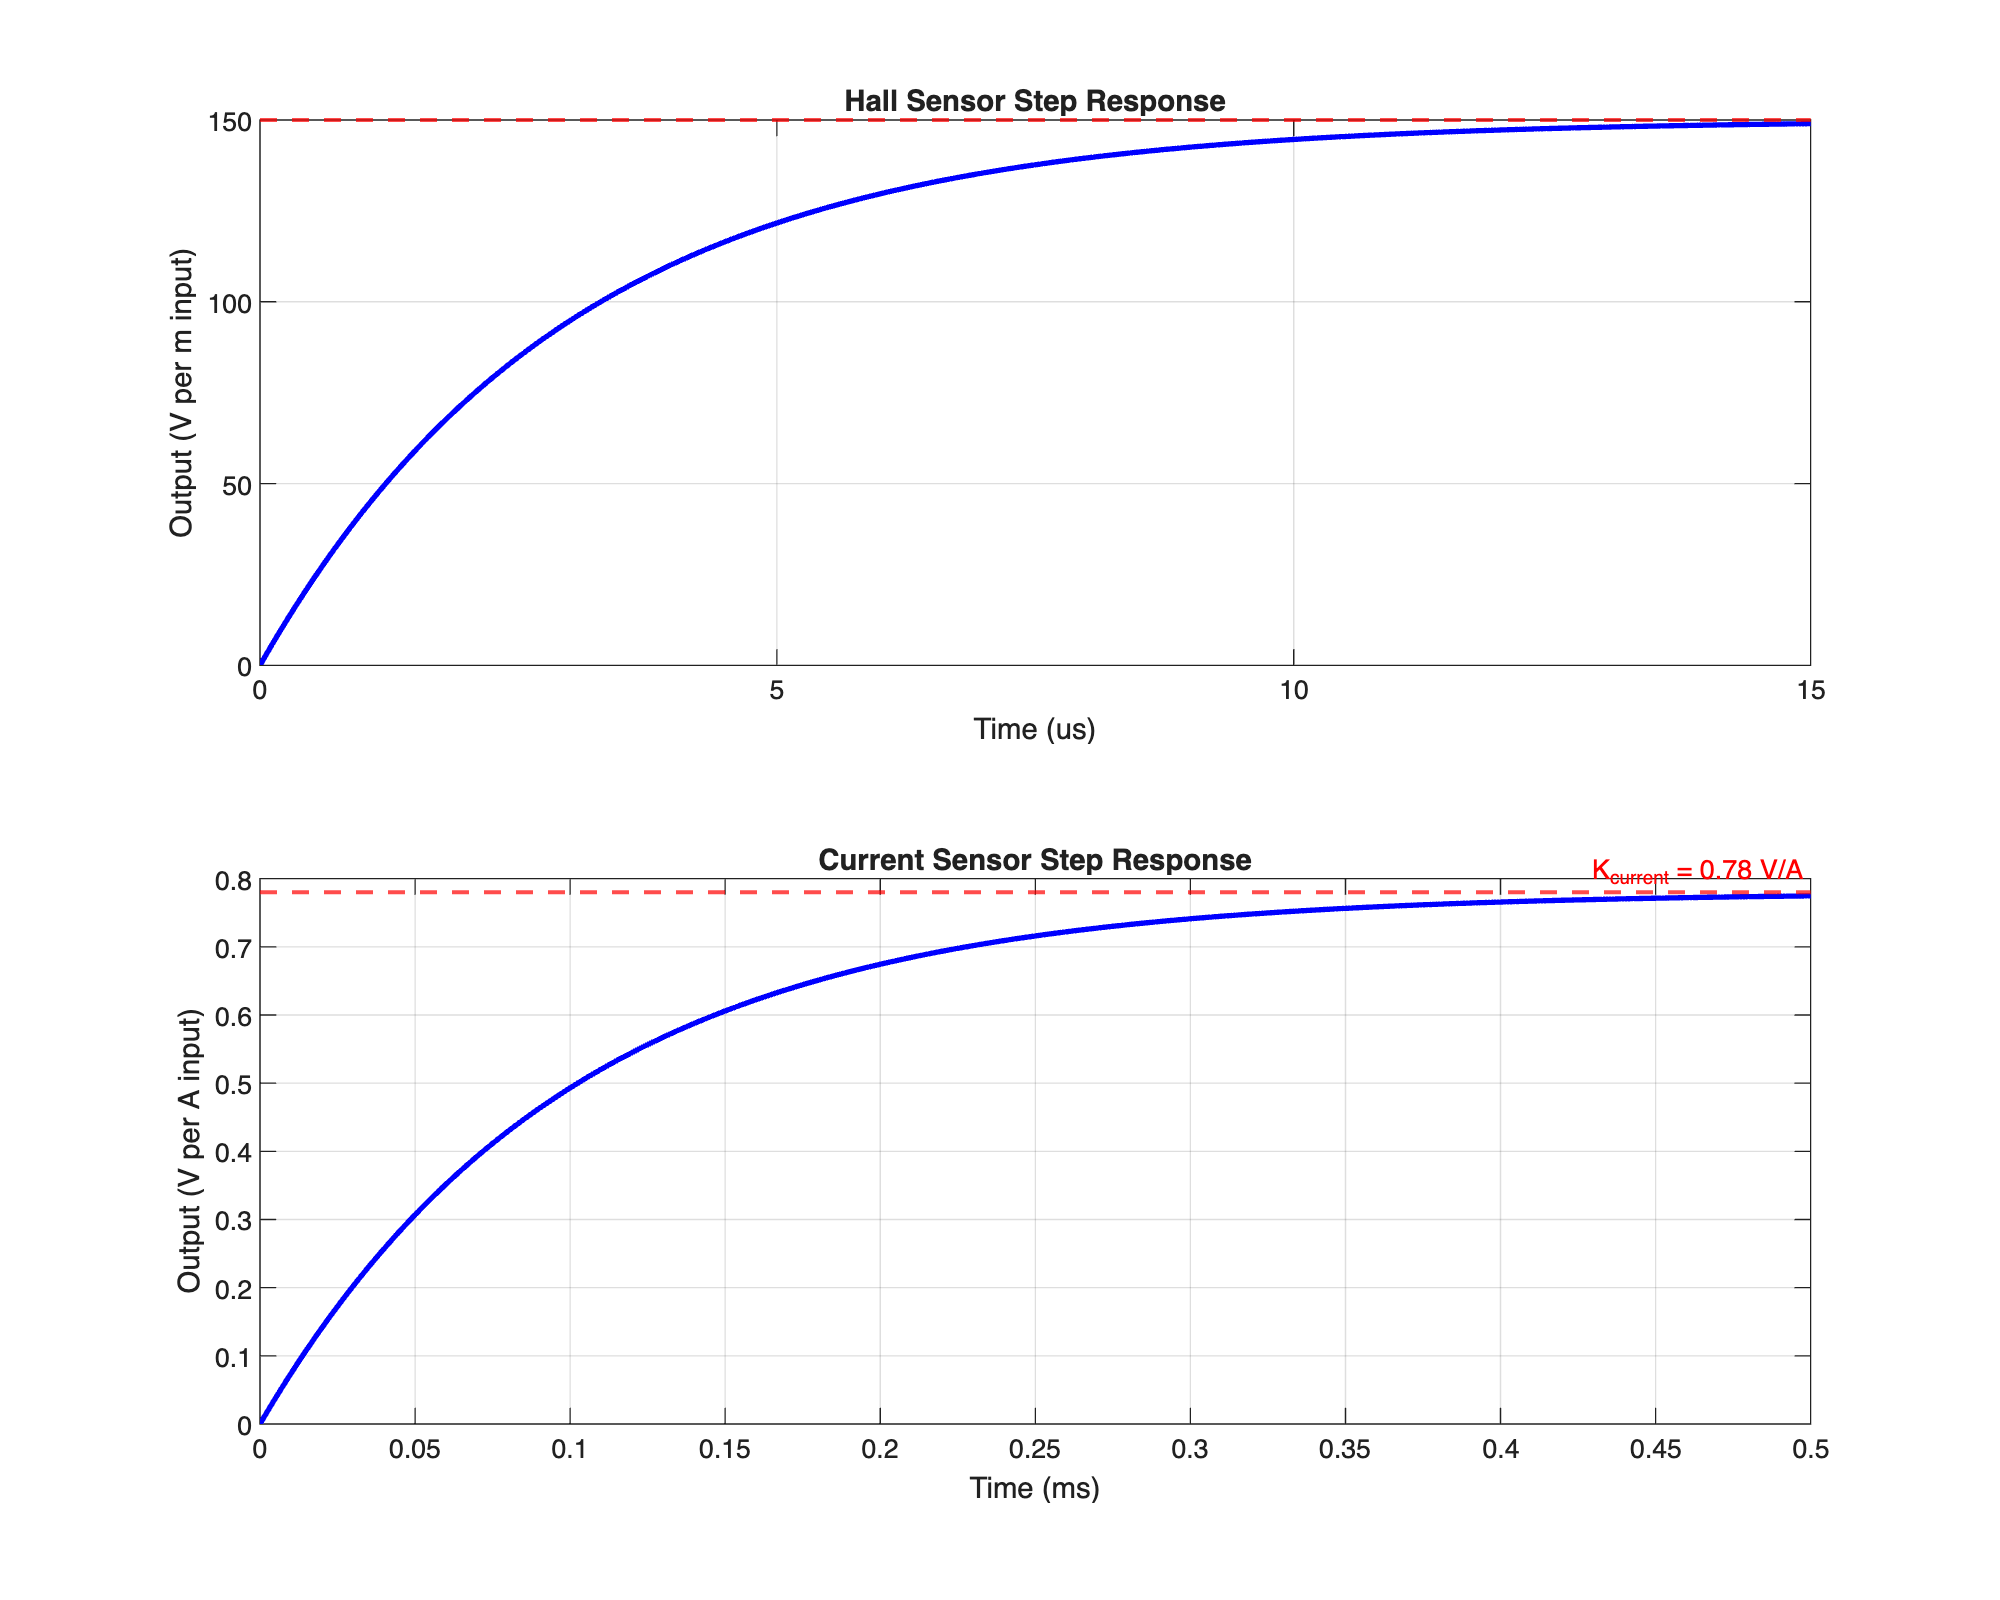


subplot(2,1,2);
t_c = linspace(0, 5*t_current, 500);
[y_c, t_c_out] = step(current_sensor_tf, t_c);
plot(t_c_out*1e3, y_c, 'b-', 'LineWidth', 2);
hold on;
yline(K_current, 'r--', sprintf('K_{current} = %.2f V/A', K_current), 'LineWidth', 1.5);
xlabel('Time (ms)');
ylabel('Output (V per A input)');
title('Current Sensor Step Response');
grid on;

### Actuators

## From a theoretical perspective, describe what measurements need to be made to your system.  

To regulate the magnetic force acting on the magnet and achieve stable levitation, the control system must be able to dynamically adjust the current flowing through the coil. Since the coil's magnetic field force equation is directly dependent on coil current, the actuator subsystem must translate the controller's digital output into a precisely controlled analog current through the coil. Two measurements are curcial to acheive this result. First, the average coil current must be known in real time for the inner loop of the cascaded controller. This is measured by the current sensing subsystem. Second, the duty cycle commanded by the controller must translate into proportional average voltage across the coil. Any nonlinearity in the PWM-to-current path (dead time, MOSFET switching delays, coil saturation) will degrade the inner loop's ability to track the commanded current setpoint.

## From a practical perspective, describe how the actuator is going to apply input to the system.  If you are going for a 75% you still need to include information about a hypothetical sensor.  

The actuator chain consists of three stages: the microcontroller generates a PWM signal, an N-channel MOSFET switches the 12V supply to the coil at the commanded duty cycle, and the coil converts the resulting current into magnetic force on the permanent magnet. The PWM is modeled as a zero-order hold with a gain equal to the supply voltage. The average voltage applied to the coil is:


$$V_{\textrm{avg}} =\textrm{Duty}\;\textrm{Cycle}*12V$$


where duty cycle ranges from 0 to 100%. This can be modelled as a gain block (x12) preceded by a saturation block clamping the input between 0 and 1. 

To drive the PWM output of the microcontroller to the high-current coil control signal, an IRLZ44N [3] N-channel logic-level MOSFET is used. When the MOSFET turns off, the coil's inductance drives a voltage spike as it attempts to maintain current flow. The IRLZ44N has a gate-source voltage of 2.5-3.3V, which will match the logic level voltage threshold of most microcontrollers. The MOSFET can be modeled as an ideal switch due to its fast switching times (~100 ns) relative to the slower frequency of the PWM period. Its drain-source resistance of around 0.022$\Omega$ will be added to the coil resistance in the electrical model.

The electromagnet is the primary actuator of the system. It consists of a certain amount of turns of a magnet wire wound on a ferromagnetic core with a coil radius. When current flows through the coil, a magnetic field is produced that attracts the permanent magnet according to the force equation derived:


$$F_{\textrm{coils}} \left(x,i\right)=\frac{3\mu_0 N{\textrm{IR}}^2 m_d x}{2{\left(x^2 +R^2 \right)}^{\frac{5}{2}} }\;$$


The coil's electrical dynamics are modeled as a first-order RL circuit:


$$L*\frac{\textrm{di}}{\textrm{dt}}=V_{\textrm{applied}} -R_{\textrm{coil}\;} *i$$


which gives the transfer function from applied voltage to current:


$$\frac{I\left(s\right)}{V\left(s\right)}=\frac{1}{\textrm{Ls}+R_{\textrm{coil}} }$$


where L is the coil inductance (to be calculated or measured), where $L=\frac{\mu N^2 A}{l}$  where $N$is the number of turns, $A$ is cross-sectional area, $l$ is coil length,  and $\mu$ is magnetic permeability of the core. and R_coil is the coil resistance (to be measured with a multimeter). The time constant of this first-order system is tau = L / R_coil. For an estimated L = 20 mH and R_coil =  5 ohm, the electrical time constant is 4 ms, corresponding to a natural bandwidth of approximately 40 Hz. The inner current loop controller is designed to increase this bandwidth significantly. 

## Include links to datasheets, figures, photos, etc.  

[3] [MOSFET](https://mm.digikey.com/Volume0/opasdata/d220001/medias/docus/1158/IRFZ24N.pdf)

*Include how you are modeling and powering the actuator.  What physical limitations are there on the actuator?  Saturation, input rates?  Include all physical limits.  *

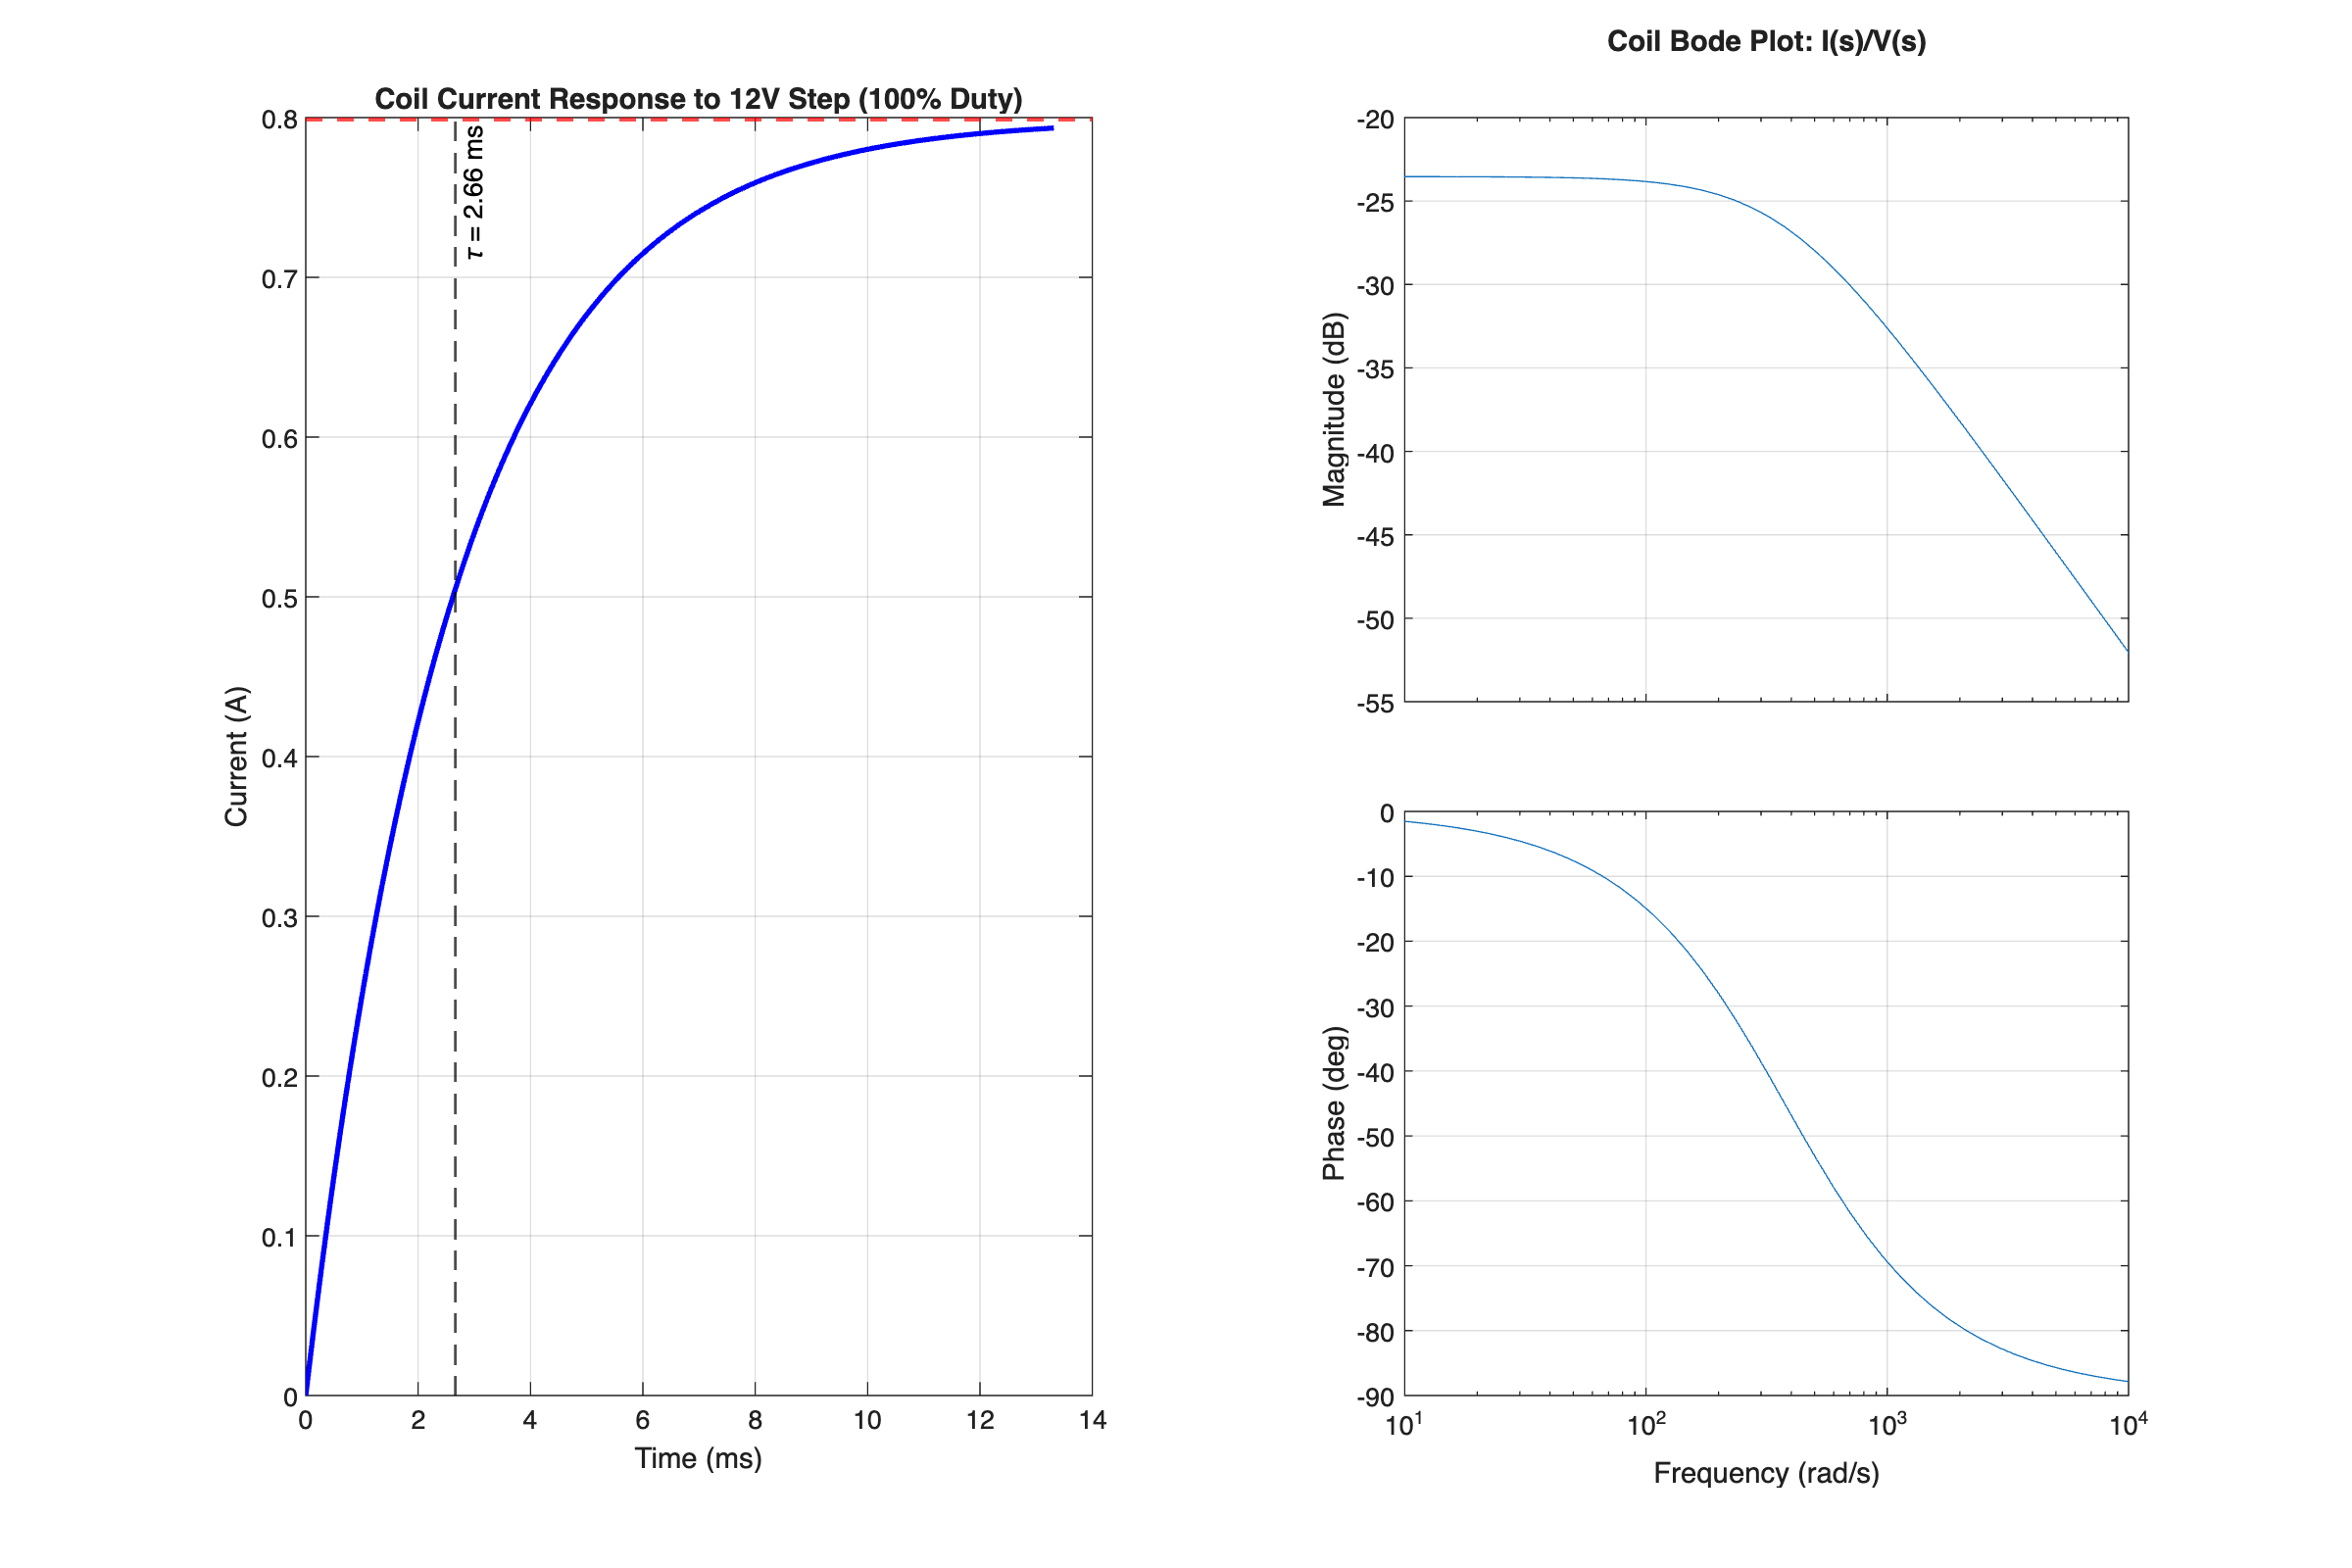

% Code! 
Rds_on = 0.022;         % MOSFET on-resistance (ohm)
R_eff = R + Rds_on;

G_coil = tf(1, [L, R_eff]);

figure('Name', 'Electromagnet Response', 'Position', [50, 50, 1200, 800]);

subplot(1,2,1);
t = linspace(0, 5*L/R_eff, 500);
[y, t_out] = step(12 * G_coil, t);  % 12V step
plot(t_out*1e3, y, 'b-', 'LineWidth', 2);
hold on;
yline(12/R_eff, 'r--', sprintf('I_{ss} = %.2f A', 12/R_eff), 'LineWidth', 1.5);
xline(L/R_eff*1e3, 'k--', sprintf('\\tau = %.2f ms', L/R_eff*1e3), 'LineWidth', 1);
xlabel('Time (ms)');
ylabel('Current (A)');
title('Coil Current Response to 12V Step (100% Duty)');
grid on;
 
subplot(1,2,2);
bode(G_coil);
grid on;
title('Coil Bode Plot: I(s)/V(s)');

### Signals

## Include any information about disturbances in your system.  

The magnetic levitator is very sensitive to disturbances due to the strong non linear relation of magnetic force on position. Some disturbances include: 

- External mechanical disturbances: Vibrations in the mounting structure or wind can introduce disturbances in the position of the magnet. The magnetic force can increase rapidly as position slightly decreases and therefore can cause instability. 

- Supply voltage variation: Fluctuations in the 12V power supply will directly affect the coil voltage and current. This can introduce disturbancers in the force applied to the magnet since the magnetic force is proportional to current. 

- Thermal effects in the coil: As the current flows through the coil, resistive heating increases the coil resistance $R_{\textrm{coil}\ldotp }$ This will reduce the current for a given voltage which can change the system dynamics over time and must be accounted for. 

- Unmodeled magnetic effects: Eddy currents in nearby conductive materials and a non-uniform magnetic field distribution may introduce disturbances not captured in the model. 

## Include a characterization of noise in your system.  

Noise enters the system through the sensing elements and the switching for the electromagnet current. 

**Hall Effect Sensor Noise:** The Hall sensor outputs an analog voltage proportional to magnetic field. Some sources of noise are electromagnetic interference (EMI), quantization noise from the 12-bit ADC, and thermal noise or sensor nonlinearities. This noise will appear in the position measurement which will directly affect the outer control loop. 

**Current Sensor Noise: **The shunt and op-amp system introduce amplifier noise, offset voltage error, or high frequency switching noise from the PWM. An RC low-pass filter (~1.6kHz cutoff) is implemented to limit this but some noise may still remain from PWM switching. 

**PWM Switching Noise:** The MOSFET switching may introduce high frequency current noise in the coil or also produce EMI near the sensors. This noise will cause measurement noise and actual current noise. 

## Include any information about gains needed to balance units (i.e. 0-12V vs 0-100%).  

**Controller Output -> Coil Voltage**: The controller outputs a duty cucle $d\in \left\lbrack 0,1\right\rbrack$ which is converted to voltage and introduces the first PWM gain, $K_{\textrm{PWM}} \ldotp$ The coil voltage is roughly $V_{\textrm{coil}} =K_{\textrm{PWM}} *d,\;$where $K_{\textrm{PWM}} =12V\ldotp$

**Coil Voltage -> Coil Current:** The RL transfer function is $\frac{I\left(s\right)}{V\left(s\right)}=\frac{1}{\textrm{Ls}+R_{\textrm{coil}} }$. At steady state, the gain is $I=\frac{V}{R_{\textrm{eff}} }\ldotp$ The DC gain of the system at zero frequency is $K_{\textrm{coil}} =\frac{1}{R_{\textrm{eff}} \ldotp }$

**Current -> Magnetic Force: **The nonlinear model is approximately $F\propto\textrm{NI}*f\left(x\right)$. This is a position dependent nonlinear gain, so the system gain changes with position and is why the system is open-loop unstable. 

**Current Sensor Scaling: **The current sensor gain is determined by the shunt resistor and op-amp gain. With a 0.1Ω shunt resistor and amplifier gain of 6.8, the resulting scaling is $V=0\ldotp 68\textrm{IV}=0\ldotp 68\textrm{IV}=0\ldotp 68I$, giving a gain $K_{\textrm{current}} =0\ldotp 78\;$*V/A*.

**Hall Sensor Scaling: **The hall sensor is modeled as $V_{\textrm{hall}} =K_{\textrm{hall}} *x$ with $K_{\textrm{hall}} \approx 150$*V/m*. However, this should also be experimentally determined by placing the magnet at known positions, recording the Hall votlage and fitting a line to measured voltage versus position data to compute the true gain. 

**ADC Conversion: **With a 3.3V reference and 12-bit ADC, the resolution is $\Delta V\approx \frac{3\ldotp 3}{4096}\approx 0\ldotp 8\textrm{mV}\ldotp$

% PWM command to coil voltage
K_pwm = 12;              % 0 to 1 duty cycle maps to 0 to 12 V
duty_min = 0;
duty_max = 1;

% Current sensor scaling
K_current_sense = 0.78;  % V/A

% ADC conversion
Vref = 3.3;
ADC_bits = 12;
ADC_counts = 2^ADC_bits;
K_adc = ADC_counts / Vref;   % counts per volt


% Example conversions
V_coil = K_pwm * 0.5;    % 50% duty = 6 V
V_sense = K_current_sense * 2;   % 2 A = 1.56 V
adc_value = V_sense * K_adc; 

### Controller

Let's not forget the start of the show!  Explain how you are implementing your controller.  

The controller for the magnetic levitation system is implemented as a cascaded two-loop controller. This means there are two control loops working together:

- an inner current loop

- an outer mechanical position loop

**Inner Loop: Inductor Current Control**

    The purpose of the inner loop is to make the actual coil current follow a desired current command quickly and accurately. The loop uses $i_{\textrm{ref}} =$desired coil current (A), $i=$ measured coil current (A), and $e_i =i_{\textrm{ref}} -i=$ current error (A). The controller then uses this error to compute the PWM duty cycle. The transfer function for the inductor current and voltage is $\frac{I\left(s\right)}{V\left(s\right)}=\frac{1}{\textrm{Ls}+R_{\textrm{coil}} }$. This means that the current has first order lag and has steady state error. Thus, a PI controller is used as a standardized method of regulating the current through the load and eliminating steady state error, so that the outer position loop does not have to also fight the electrical lag. 

    A PI controller is used $C_i \left(s\right)=K_{p,i} +\frac{K_{i,i} }{s}$ where $K_{p,i}$ is proportional gain for the current loop and $K_{i,i}$ is integral gain for the current loop. The proportional term reacts to present current error and the integral term removes steady-state current error. The controller output is the duty cycle command: $d=$$K_{p,i} e_i +K_{i,i} \int e_i \textrm{dt}\;$where $d$= PWM duty cycle [0,1] and $e_i$=current error (A). The duty cycle is limited so that $0\le d\le 1$ corresponding to the physical range of 0-100% duty cycle. This PWM output will then drive the mosfet and create an average coil voltage $v=12d\ldotp$

**Outer Loop: Mechanical Magnet Position Control**

    The outer loop controls the actual magnet position. The loop uses $x_{\textrm{ref}} =$desired magnet position (m), $x=$measured magnet position (m), and $e_x =x_{\textrm{ref}} -x=$position error (m). The output of this loop is desired inductor current $i_{\textrm{ref}} \;$since the actuator physics and produced electromagnetic force is based on coil current. The vertical motion of the magnet is governed by Newtown's second law and the equation previously defined: $m\ddot{x} =F_{\textrm{mag}} \left(i,x\right)-\textrm{mg}$ which is nonlinear because the  magnetic force depends on current and position of the magnet. 

    The Hall sensor does not directly measure position. Rather, it measures magnetic field strength which is converted to an estimated real time magnet position through calibration and fitting the line between position and magnetic field. The calibrated relationship can be approximated as $V_{\textrm{hall}} \approx K_{\textrm{hall}} x+b$ or equivalently $x\approx \frac{V_{\textrm{hall}} -b}{K_{\textrm{hall}} }$ where $K_{\textrm{hall}} =$Hall sensor calibration slope in V/m and $b=$offset voltage from calibration, about the $\frac{\textrm{Vcc}}{2}$ point. Thus, the outer loop is using estimated position derived from measured magnetic field. 

    A PID controller will be used of the form $i_{\textrm{ref}} =$$K_{p,x} e_x +K_{i,x} \int e_x \textrm{dt}\;+K_{d,x} \frac{{\textrm{de}}_x }{\textrm{dt}}$ where $K_{p,x}$,${\;K}_{i,x}$, $K_{d,x}$ is proprtional gain, integral gain, and derivative gain, respectively and $i_{\textrm{ref}}$ is desired current (A). The proportional term reacts to present position error, the integral term removes steady-state error, and the derivative term adds damping by reacting to how fast the error is changing. The derivative term will counteract rapid changes in the error signal and predict future errors, thereby reducing overshoot, oscillations, and settling time to stabliize the inherently unstable open loop system. 

- Include a description for in Simulation

In simulation, the controller is implemented using blocks to represent the cascaded controller and the system dynamics. 

- A reference position $x_{\textrm{ref}}$ is set. 

- The simulated Hall sensor model, with gain, produces a measured position $x$. 

- The position controller computes $i_{\textrm{ref}}$. 

- The measured current $i$ is compared to $i_{\textrm{ref}}$. 

- The current controller computes the duty cycle $d$. 

- A saturation block limits duty cycle to the interval [0,1]. 

- A gain block multiplies duty cycle by 12 to produce coil voltage: $v=12d$

- The RL coil model produces the current response: $\frac{I\left(s\right)}{V\left(s\right)}=\frac{1}{\textrm{Ls}+R_{\textrm{coil}} }$

- The nonlinear magnetic force block computes $F_{\textrm{mag}} \left(i,x\right)$

- The mechanical plant integrates acceleration to velocity and position using: $m\ddot{x} =F_{\textrm{mag}} \left(i,x\right)-\textrm{mg}$

- Include a description for hardware (if >75%)

    In hardware, the controller is implemented digitally on the microcontroller. 

- The Hall-effect sensor voltage is read using the ADC. 

- That voltage is converted through the calibration equation into estimated position $x$.

- The current sensor voltage is read using the ADC.

- That voltage is converted into measured current $i$. 

- The position controller computes the desired current $i_{\textrm{ref}}$. 

- The current controller computes the PWM duty cycle $d$. 

- The PWM signal is updated and drives the MOSFET gate. 

- The coil current changes, changing magnetic force and magnet position.

    The inner current loop should be faster than the outer loop becuase the inductor current dynamics change much quicker than the mechanical position dynamics. Therefore, the inner loop can run at 10kHz while the outer loop can be polled at 1kHz. 

% Code!
Kp_x_dummy = -10;
Ki_x_dummy = -1;
Kd_x_dummy = 0;
Kp_i_dummy = 10;
Ki_i_dummy = 0;

### A Golden Model

*Create a diagram of your golden model.  *The easiest and most practical way to do this is to use a screenshot from your labeled Simulink simulation.  

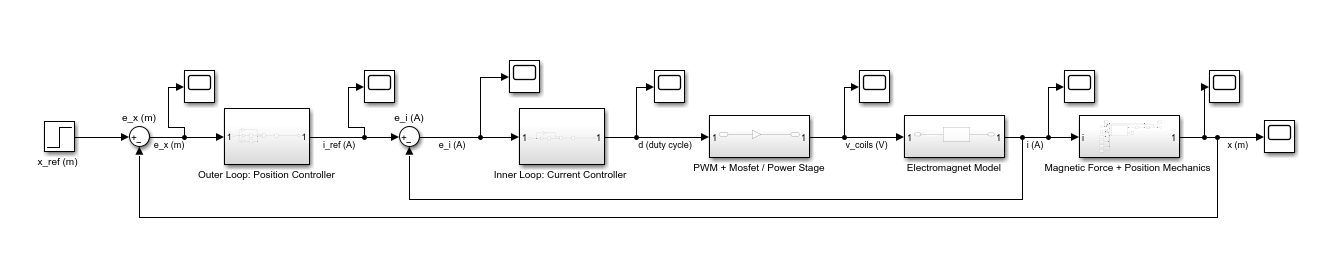

How do you make visual code easy to read?  Make sure to use subsystems, add figures to the subsystems, add words to label.  

Your simulation should be a collection of everything you have done above.  You can use a "dummy" controller (i.e. Kp=1).  Be sure to include noise and disturbances.  

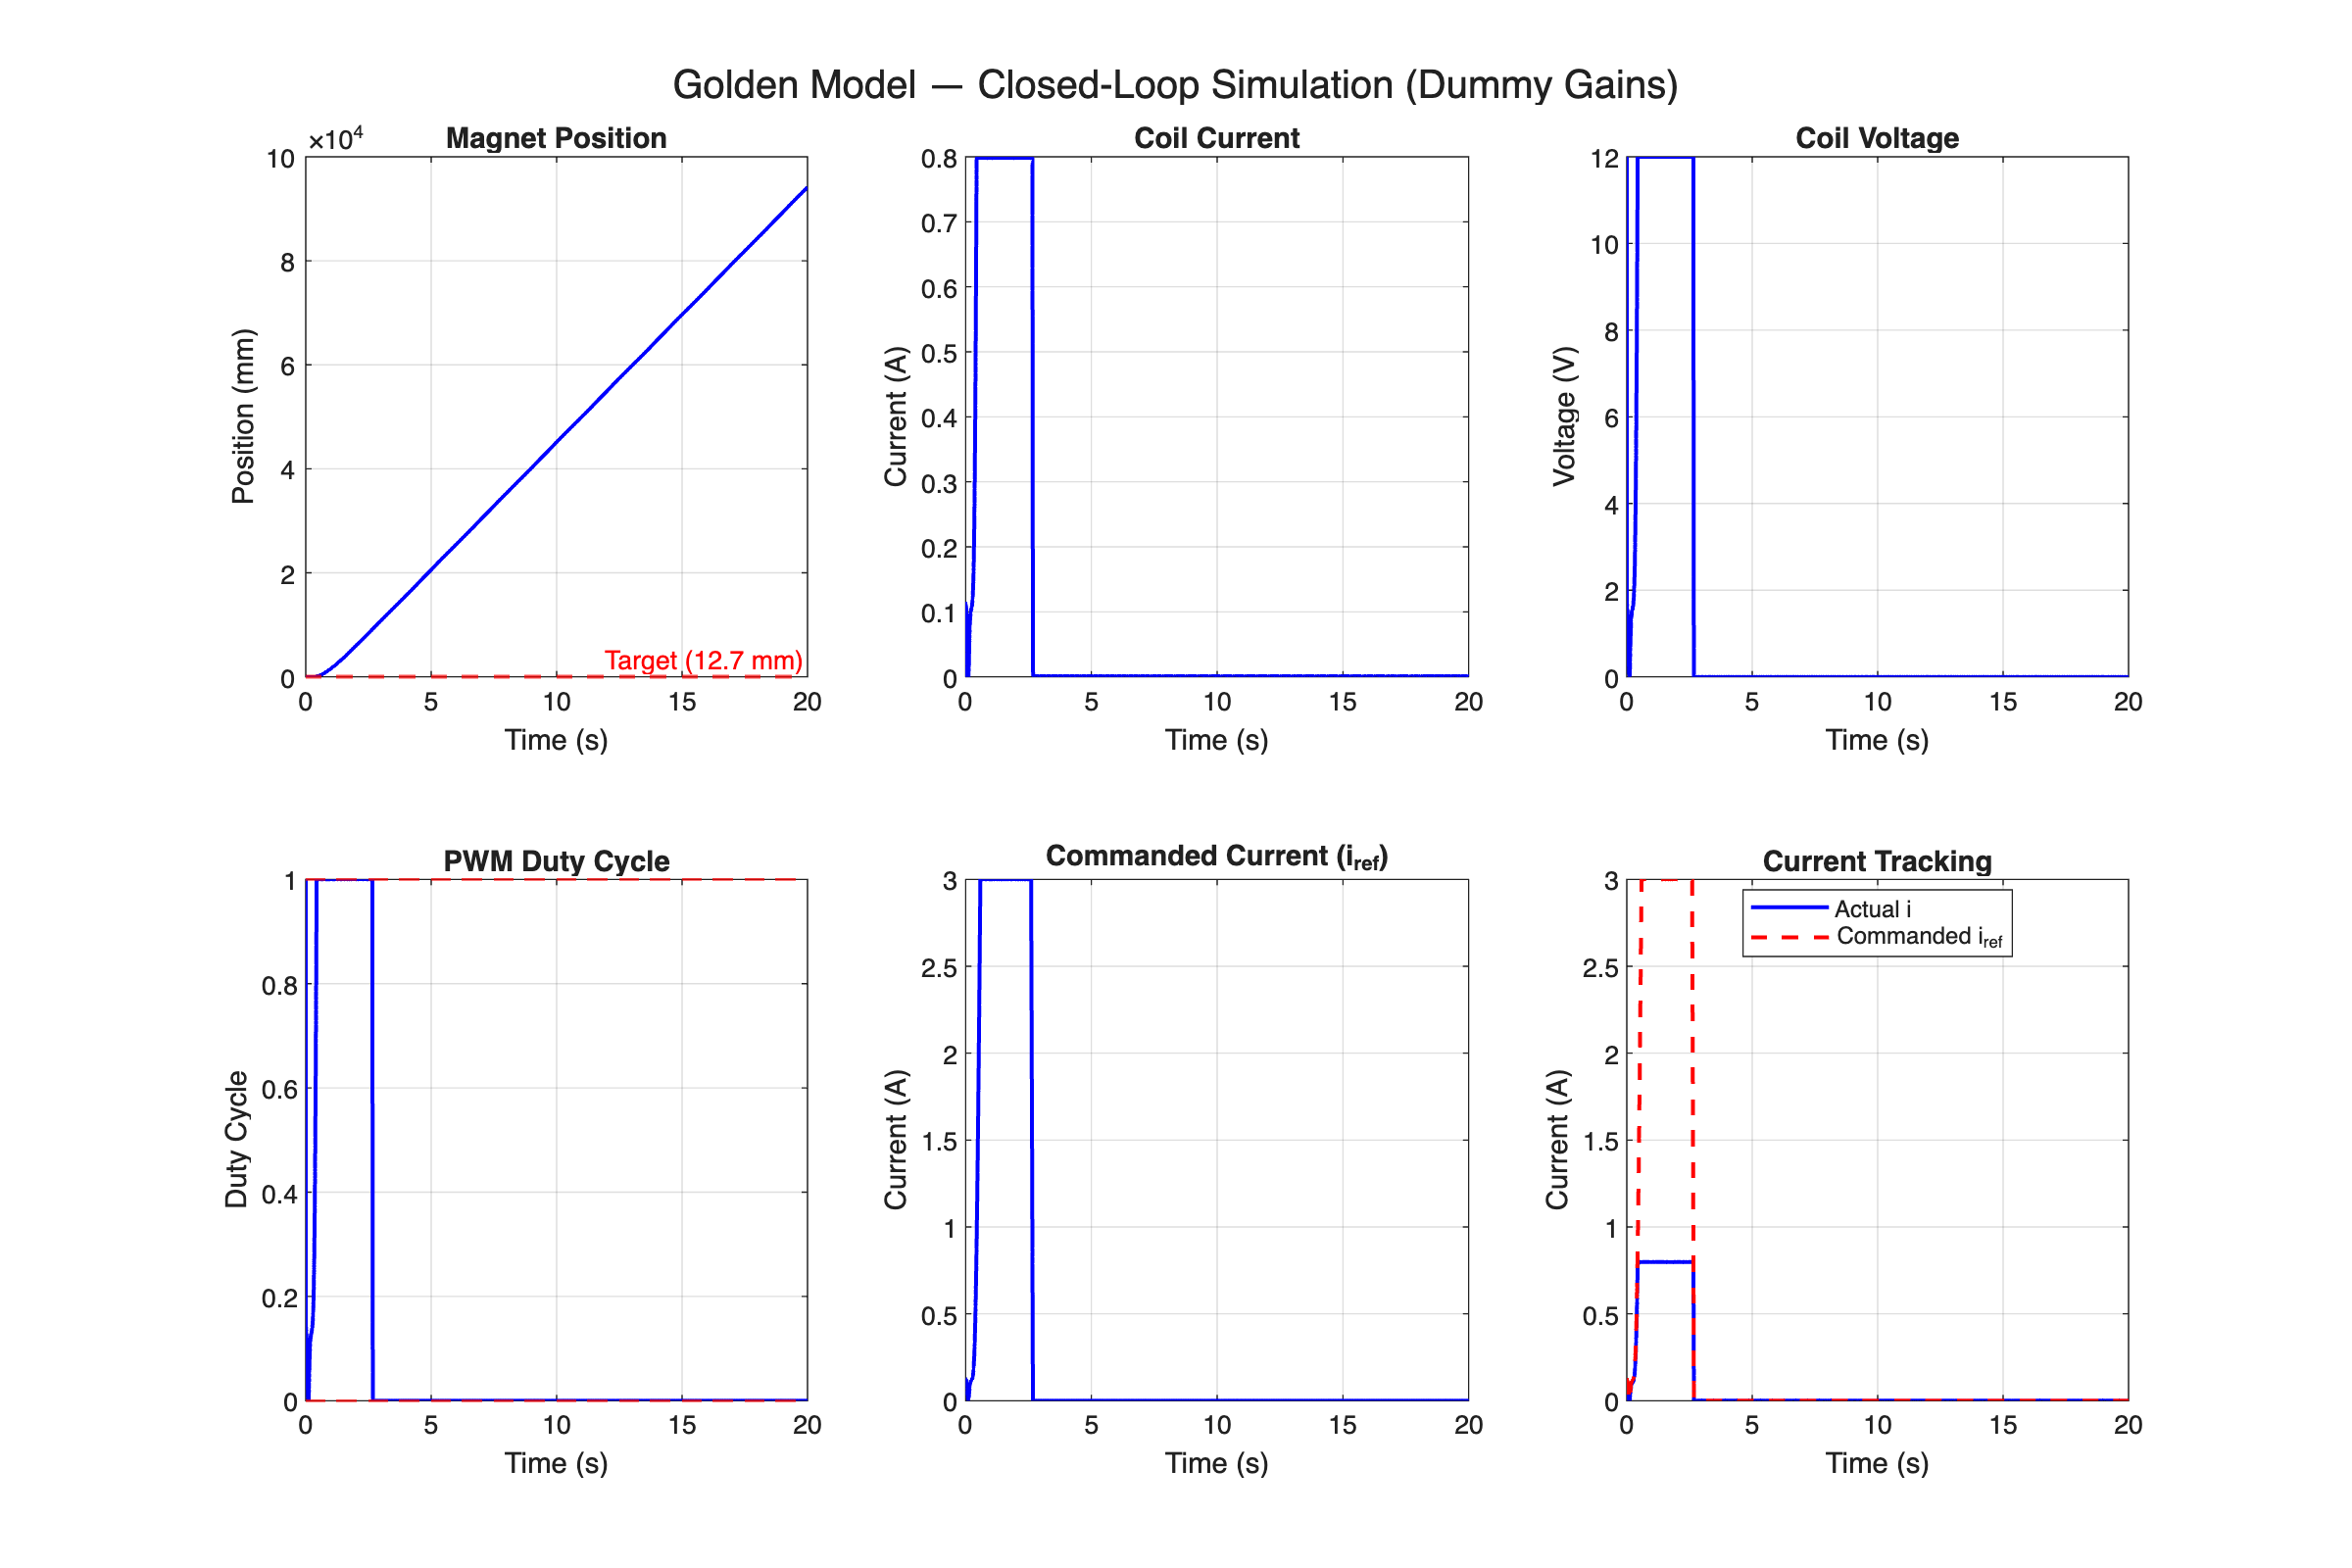


% Mechanical damping
b_mech = 0.02;         % Mechanical damping [N*s/m]
xdot0 = 0.0;           % Initial velocity [m/s]

% Supply voltage
Vsup = 12;             % Supply voltage [V]
duty_cycle = 1.0;      

% Sensor biases
hall_bias = 1.65;       % Hall sensor bias [V]
tau_hall = 3e-6;        % Hall sensor time constant [s]
tau_current = 1e-4;     % Current sensor time constant [s]

% Noise / disturbance
hall_noise_power = 1e-6;
current_noise_power = 1e-6;
Fdist_amp = 0.01;       % Disturbance force amplitude [N]

model_name = 'Golden_Model';
out = sim(model_name);

% Extract data
time_gm = out.simout.Time;
pos_gm = out.simout.Data;
current_gm = out.simout_current.Data;
duty_gm = out.simout_duty.Data;
iref_gm = out.simout_iref.Data;
voltage_gm = out.simout_voltage.Data;

% Plot
figure('Name', 'Golden Model Results', 'Position', [100, 100, 1200, 800]);

subplot(2,3,1);
plot(time_gm, pos_gm*1000, 'b-', 'LineWidth', 1.5);
hold on;
yline(x0*1000, 'r--', sprintf('Target (%.1f mm)', x0*1000), 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Position (mm)');
title('Magnet Position'); grid on;

subplot(2,3,2);
plot(time_gm, current_gm, 'b-', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Current (A)');
title('Coil Current'); grid on;

subplot(2,3,3);
plot(time_gm, voltage_gm, 'b-', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Voltage (V)');
title('Coil Voltage'); grid on;

subplot(2,3,4);
plot(time_gm, duty_gm, 'b-', 'LineWidth', 1.5);
yline(1, 'r--', 'Saturation', 'LineWidth', 1);
yline(0, 'r--', '', 'LineWidth', 1);
xlabel('Time (s)'); ylabel('Duty Cycle');
title('PWM Duty Cycle'); grid on;

subplot(2,3,5);
plot(time_gm, iref_gm, 'b-', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Current (A)');
title('Commanded Current (i_{ref})'); grid on;

subplot(2,3,6);
plot(time_gm, current_gm, 'b-', 'LineWidth', 1.5);
hold on;
plot(time_gm, iref_gm, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Current (A)');
title('Current Tracking'); grid on;
legend('Actual i', 'Commanded i_{ref}', 'Location', 'best');

sgtitle('Golden Model — Closed-Loop Simulation (Dummy Gains)');

### Simscape Simulation

At this point we should be able to have a full simulation!  Unlock the power of Simulink with Simscape to make a graphical demonstration of your final project.  

Follow the examples in class.  

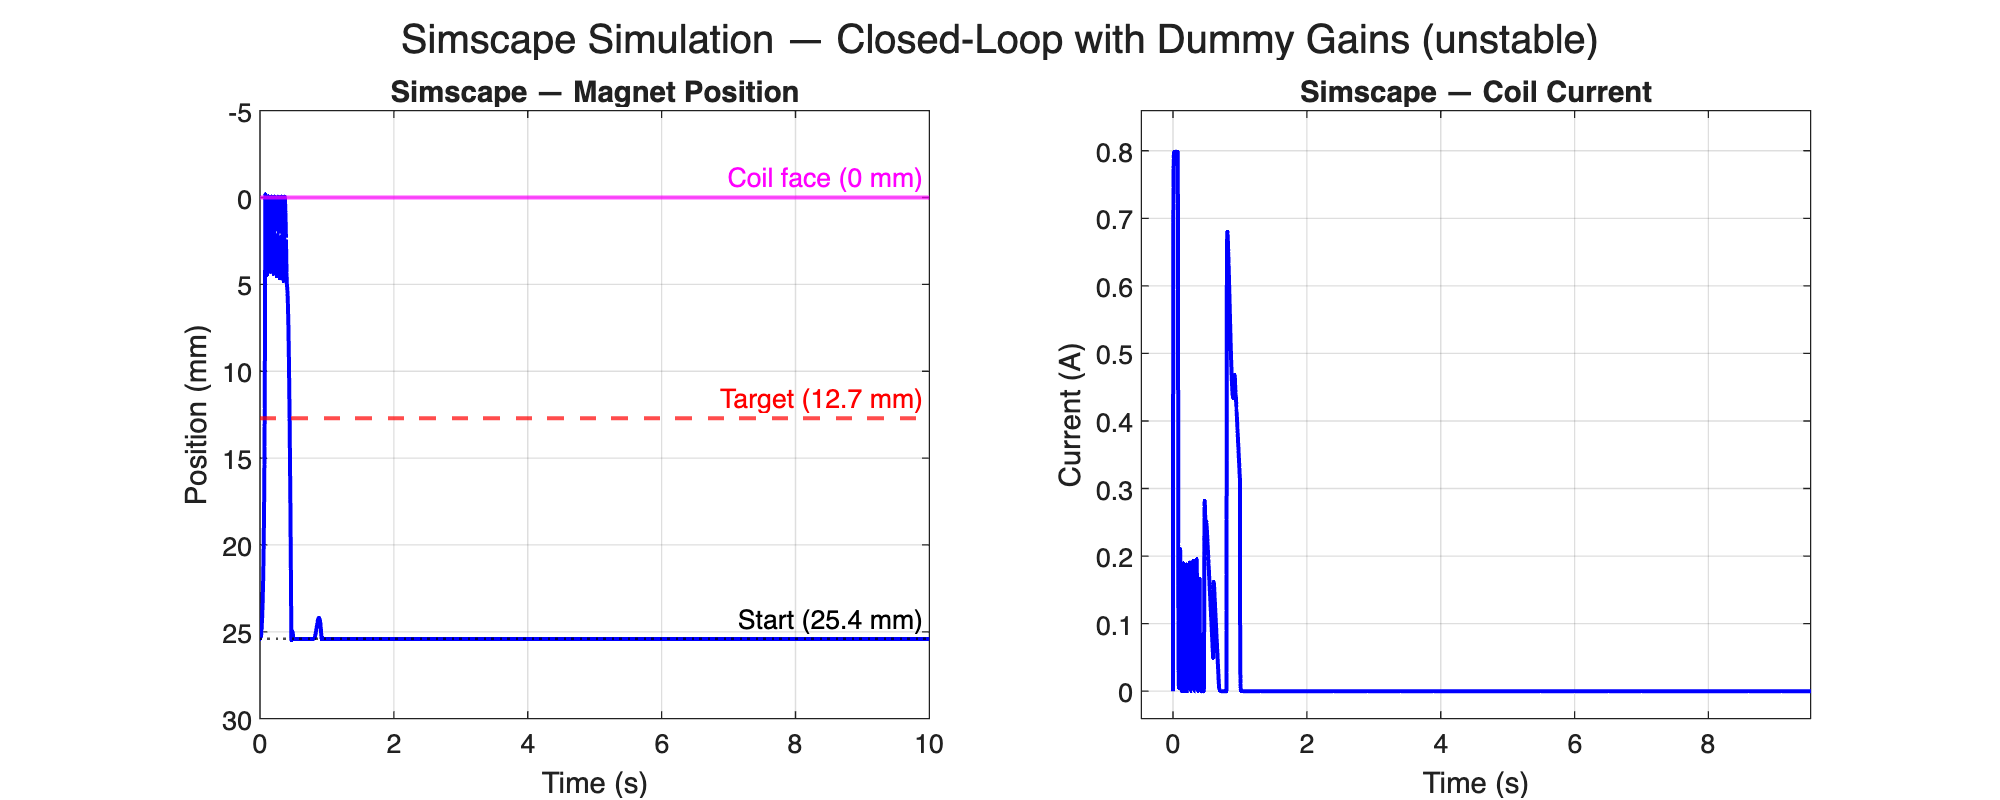

% Code! 

model_name = 'MagLev_Simscape';
out_sc = sim(model_name);

% Extract data
time_sc = out_sc.simout_pos.Time;
pos_sc = out_sc.simout_pos.Data;
current_sc = out_sc.simout_current.Data;

% Plot
figure('Name', 'Simscape Results', 'Position', [100, 100, 1000, 400]);

subplot(1,2,1);
plot(time_sc, pos_sc*1000, 'b-', 'LineWidth', 1.5);
hold on;
yline(x0*1000, 'r--', sprintf('Target (%.1f mm)', x0*1000), 'LineWidth', 1.5);
yline(pos_sc(1)*1000, 'k:', sprintf('Start (%.1f mm)', pos_sc(1)*1000), 'LineWidth', 1);
yline(0, 'm-', 'Coil face (0 mm)', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Position (mm)');
title('Simscape — Magnet Position'); grid on;
set(gca, 'YDir', 'reverse');
ylim([-3, pos_sc(1)*1000 + 3]);

subplot(1,2,2);
plot(time_sc, current_sc, 'b-', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Current (A)');
title('Simscape — Coil Current'); grid on;

sgtitle('Simscape Simulation — Closed-Loop with Dummy Gains (unstable)');

### Hardware time

If you are going for above a 75% you need to have a good start on your plant.  

If you are going for an 85% you can use the material Dr. Trudgen has posted on ELC.  

*Include documentation showing progress on the plant.  *

    For the plant, the group has wound their electromagnet using a large steel bolt as the core and 30 gauge copper wire for the coils. The group wound it by hand, around 1000 turns. The group has tested inductor current capabilties through it to begin characterizing the Current Control loop, but is limited by the lower voltage and current capabilities of the traditional voltage supply. The group is going to pivot to using the wall power supply and the shunt resistor to characterize these curves. The group has ordered a PCB for the power supply and all the sensors. The group obtained a magnet from Dr. Trudgen. The next large step of this week is ensuring that the inner current control loop works before moving to the outer position loop. 

## Checkpoint 3: Controller Design

Recall the first goal of a feedback controller is stability.  After that its performance and robustness.  

Earlier in this documentation you have characterized the behavior of the open-loop system.  Make any changes as needed to parameters now that you have built a plant.  

### Closed-Loop Goals

Describe your goals for the controller.  In full disclosure here, Dr. Trudgen will use good judgment to subjectively grade.  For example, if you have a very difficult plant, getting it to be stable will be the same level of difficulty as providing good performance for a more benign system.  

**   Goals**

The goal for this controller would be for it to have the ability to 

**   Controller Tuning**

     The controller gains are designed using a two-stage pole placement approach on the linearized plant model. For the inner current loop, the PI controller converts the first-order RL coil dynamics into a second-order closed-loop system. The desired closed-loop characteristic equation $s^2 +2\zeta \omega_n s+\omega_n^2 =0$ is matched to the actual characteristic equation 


$$s^2 +\left(\frac{\left(R_{\textrm{eff}} +12K_{p_i } \right)}{L}\right)\left(\frac{\left(s+12K_{i_i } \right)}{L}\right)=0$$


     by choosing $\zeta =1$ (critically damped) and $\omega_n =800\;\frac{\textrm{rads}}{s}$ (corresponding to a 5 ms settling time, which is 5x faster than the unstable mechanical pole's 25 ms time constant). Solving yields$K_{p_i }$` = `$\frac{\;2\zeta \omega_n L-R_{\textrm{eff}} }{12}\;$ and $K_{i_i }$` = `$\frac{\omega_n^2 L}{12}$ . For the outer position loop, the PID controller with the second-order unstable plant creates a third-order closed-loop characteristic equation 


$$s^3 +\beta K_{d_x } s^2 +\left(-\alpha +\beta K_{p_x } \right)s+\beta K_{i_x } =0$$


     The desired overshoot specification is converted to a damping ratio using $\zeta =\frac{-\ln \left(\textrm{OS}\right)}{\sqrt{\pi^2 +{\ln \left(\textrm{OS}\right)}^2 }}$, and the settling time specification determines the natural frequency through $\omega_n =\frac{4}{\zeta t_s }$. A dominant pole pair is placed at $s=-\zeta \omega_n \pm j\omega_n \sqrt{1-\zeta^2 }$ and a third non-dominant pole is placed further into the left half plane at $s=-p$, giving a desired polynomial whose coefficients are             matched to extract ${K_d }_x =\frac{a_2 }{\beta },K_{p_s } =\frac{a_1 +\alpha }{\beta },K_{i_x } =\frac{a_0 }{\beta }$. Because the pole placement assumes an ideal inner loop with unity gain and no phase lag, the analytical gains serve as a starting point that requires empirical refinemen. In particular, the derivative gain is increased beyond the calculated value to compensate for the additional phase delay introduced by the real inner loop dynamics. On physical hardware, the gains are further adjusted through experimental tuning to account for model uncertainties, sensor noise, actuator saturation, and nonlinear effects that the linearized transfer function does not capture.

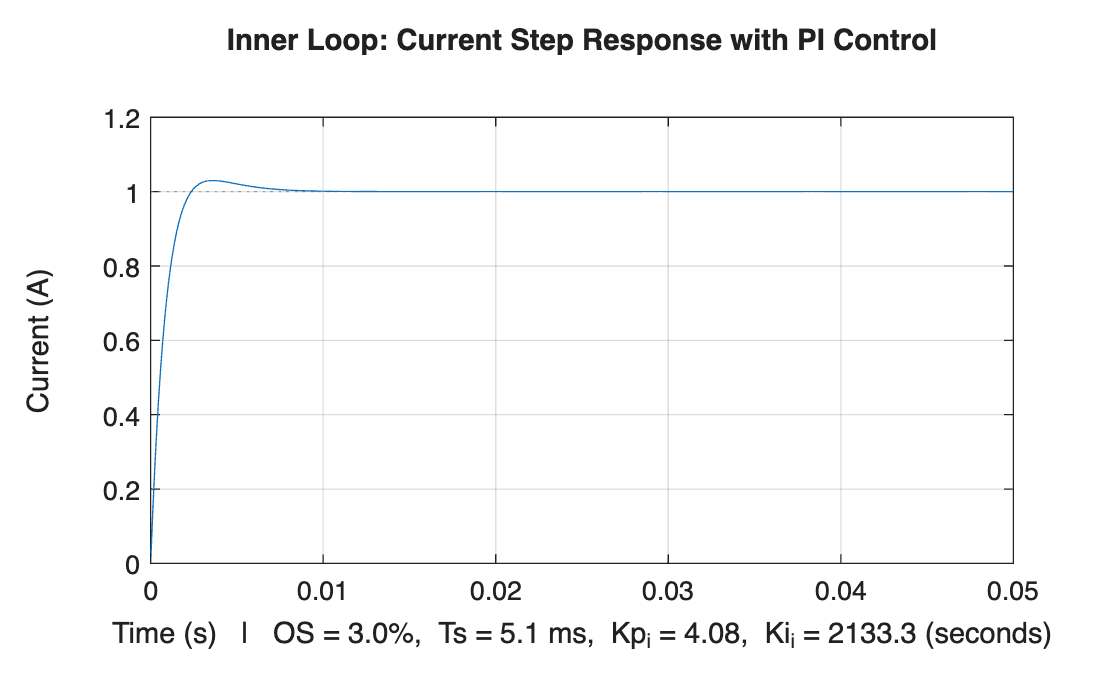

% Code!
%% Equilibrium Point
I_eq = m*g*(x0^2 + R_coil^2)^(5/2) / (K_force * x0);
V_eq = R_eff * I_eq;

% Linearization
dFdx = K_force * I_eq * (R_coil^2 - 4*x0^2) / (x0^2 + R_coil^2)^(7/2);
dFdI = K_force * x0 / (x0^2 + R_coil^2)^(5/2);
alpha = -dFdx / m;     % positive => unstable
beta  = -dFdI / m;     % negative => more current pulls magnet up

% Plant transfer functions
G_plant = tf(beta, [1 0 -alpha]);           % I -> x  (mechanical)
G_pwm = 12;                                 % duty cycle -> voltage

%% Inner Loop Design (PI) — pole placement on 1st order plant
% Specs
ts_i    = 0.005;              % settling time < 5 ms
zeta_i  = 1.0;                % critically damped

sigma_i = 4 / ts_i;           % required zeta*wn
wn_i    = sigma_i / zeta_i;

Kp_i = (2*zeta_i*wn_i*L - R_eff) / 12;
Ki_i = wn_i^2 * L / 12;

C_i = pid(Kp_i, Ki_i);
G_inner_OL = G_pwm * G_coil;
G_inner_CL = feedback(C_i * G_inner_OL, 1);

% Inner loop plot
figure('Name', 'Inner Loop Step Response');
step(G_inner_CL, 0.05);
title('Inner Loop: Current Step Response with PI Control');
ylabel('Current (A)'); grid on;
S_i = stepinfo(G_inner_CL);
xlabel(sprintf('Time (s)   |   OS = %.1f%%,  Ts = %.1f ms,  Kp_i = %.2f,  Ki_i = %.1f', ...
    S_i.Overshoot, S_i.SettlingTime*1000, Kp_i, Ki_i));

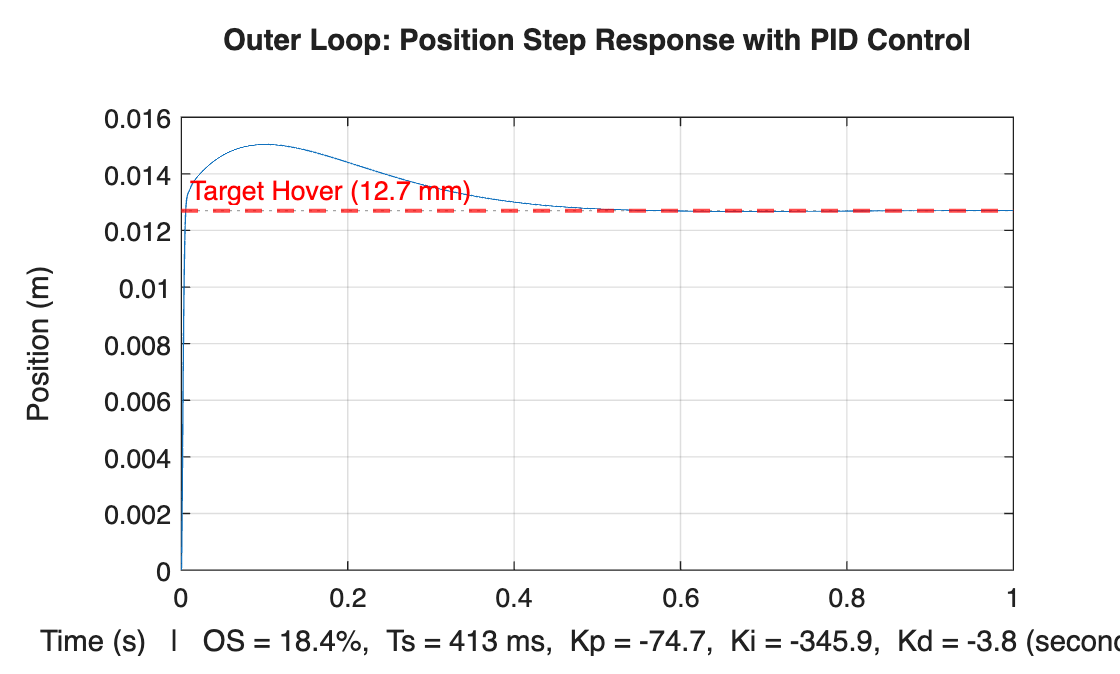


%% Outer Loop Design (PID) — pole placement on 2nd order plant
% Specs
OS_x    = 0.01;               % overshoot < 1%
ts_x    = 0.5;                % settling time < 500 ms

% Compute zeta from overshoot
zeta_x  = -log(OS_x) / sqrt(pi^2 + log(OS_x)^2);

% Compute wn from settling time
sigma_x = 4 / ts_x;
wn_x    = sigma_x / zeta_x;

% Third pole placement
p_third = 50 * sigma_x;

% Desired characteristic polynomial coefficients:
%   (s^2 + 2*zeta*wn*s + wn^2)(s + p) = 0
%   = s^3 + a2*s^2 + a1*s + a0
a2 = p_third + 2*zeta_x*wn_x;
a1 = wn_x^2 + 2*zeta_x*wn_x*p_third;
a0 = wn_x^2 * p_third;

% Match to CL char. eqn: s^3 + beta*Kd*s^2 + (-alpha+beta*Kp)*s + beta*Ki = 0
Kd_x = a2 / beta;
Kp_x = (a1 + alpha) / beta;
Ki_x = a0 / beta;

C_x = pid(Kp_x, Ki_x, Kd_x);
G_outer_OL_plant = G_inner_CL * G_plant;
G_outer_CL = feedback(C_x * G_outer_OL_plant, 1);

% Outer loop plot
figure('Name', 'Outer Loop Step Response');
step(x0 * G_outer_CL, 1);
yline(x0, 'r--', 'Target Hover (12.7 mm)', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left');
title('Outer Loop: Position Step Response with PID Control');
ylabel('Position (m)'); grid on;
S_x = stepinfo(G_outer_CL);
xlabel(sprintf('Time (s)   |   OS = %.1f%%,  Ts = %.0f ms,  Kp = %.1f,  Ki = %.1f,  Kd = %.1f', ...
    S_x.Overshoot, S_x.SettlingTime*1000, Kp_x, Ki_x, Kd_x));

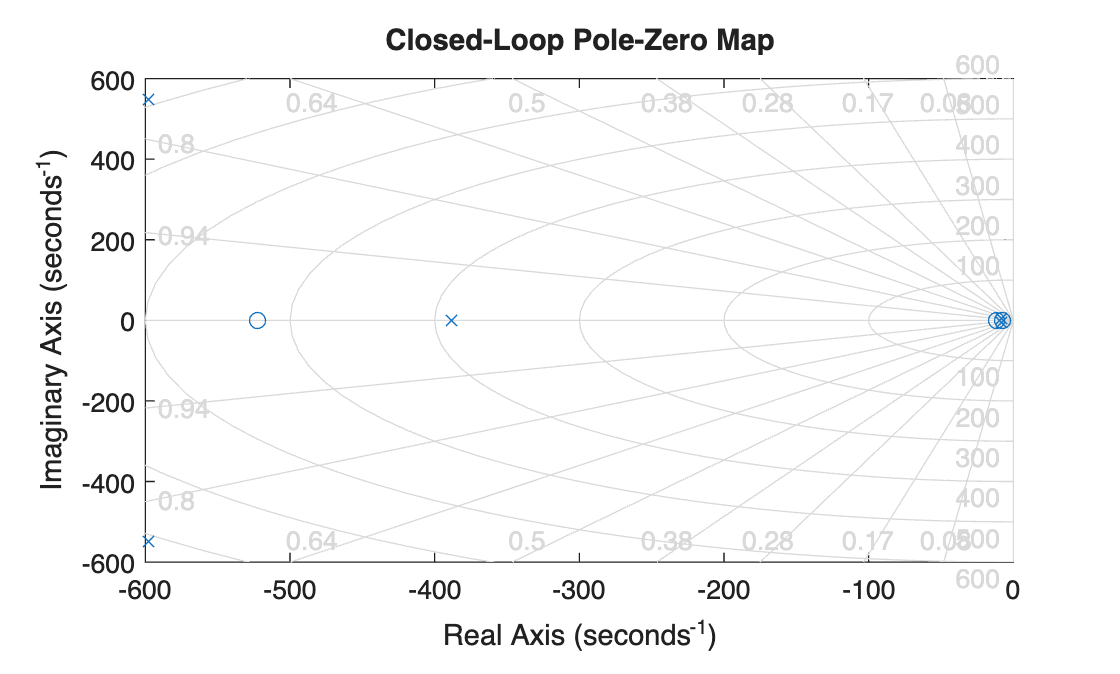


figure('Name', 'Closed-Loop Poles');
pzmap(G_outer_CL);
title('Closed-Loop Pole-Zero Map'); grid on;


% gains for Simulink (variable names match gain block names)
% These are read by the gain blocks inside the Golden_Model subsystems
Kp_i_sim = Kp_i;     % -> "K_p,i" block in Inner Loop subsystem
Ki_i_sim = Ki_i;      % -> "K_i,i" block in Inner Loop subsystem

Kp_x_sim = Kp_x;     % -> "K_p,x" block in Outer Loop subsystem
Ki_x_sim = Ki_x;      % -> "K_i,x" block in Outer Loop subsystem
Kd_x_sim = Kd_x;      % -> "K_d,x" block in Outer Loop subsystem

### Time Domain

Provide your desired time domain metrics and a brief justification.  I.e. Overshoot <5%, settling time less than 3 sec with zero steady-state error.  

Provide a pole/zero map and analysis from your Root Locus analysis to design a controller.  

Describe the controller and justify the order and realizability of the controller.

% Code! 

### Frequency Domain

Provide your desired frequency domain metrics and a brief justification.  I.e. Gain and Phase Margins.  

Provide appropriate plots and analysis here from Control System Designer.  

Describe the controller and justify the order and realizability of the controller.

% Code

### Hardware time

If you are going for above a 75% you need to have a good start on your plant and sensors/actuators/microcontroller.  

If you are going for an 85% you can use the material Dr. Trudgen has posted on ELC.  

*Include documentation showing closed-loop is possible.  *

## Demonstration Day: Closed-Loop Results

Today is the day!  You have modeled your system, carefully selection the components around it, and calculated a controller to improve the closed-loop performance.  Now time to show it off! 

All student regardless of the tier will need to sign up for a timeslot on 4/21 or 4/23 to demo.  

### Simscape Simulation

Include final documentation your full simulation.  This should include:

- A final open-loop transfer function.  

- A final closed-loop transfer function.

- All useful plots (showing time and frequency performance)

- A video showing your simscape simulation.  

- A final analysis of the system. 

% Code! 

### Experimental Results (if applicable)

Include a video of a working setup.  

- Overlay experimental data with theoretical data.  

- You've worked very hard, include any relevant analysis.  

% Code! 

### Closing Thoughts 

This project was a journey!  Feel free to share any thoughts about the journey.  Include Rev2 ideas.  

Finally, include a photo of your final setup.  

"THANK YOU for your participation in this class!  You answered the call of the moral imperative and I look forward to the good you will do!  God bless!"  Dr. Trudgen

## Resources

[1] [Magnetic Field of a Current Loop, Openstax](https://openstax.org/books/university-physics-volume-2/pages/12-4-magnetic-field-of-a-current-loop) 

[2] [Gradient and Partial Derivative, Khan Academy ](https://www.khanacademy.org/math/multivariable-calculus/multivariable-derivatives/partial-derivative-and-gradient-articles/a/the-gradient)

[3] [Magnetic Moment, Wikipedia](https://en.wikipedia.org/wiki/Magnetic_moment)

[4] [Magnetic Levitation History, Wikipedia](https://en.wikipedia.org/wiki/Maglev)